
IMPROVED BREATHING DETECTION WITH BEAMFORMING

Using file path: I:\rl_channel_test.wav
Processing file: I:\rl_channel_test.wav
Audio file details: Duration=10.14 sec, Channels=4, SampleRate=48000 Hz
Skipped initial 0.5 seconds to avoid transient artifacts
Using 6.7cm array with center origin:
  Mic 1: (0.034, -0.034, 0.000)m
  Mic 2: (-0.034, -0.034, 0.000)m
  Mic 3: (0.034, 0.034, 0.034)m
  Mic 4: (-0.034, 0.034, 0.034)m
Applying optimized MEMS filter: 80-800 Hz
Estimated DOA: azimuth = 0.0 degrees, elevation = 0.0 degrees
Simple DOA estimate: azimuth = 245.4 degrees, elevation = 65.0 degrees
Comparing DOA methods: GCC-PHAT [0.0°, 0.0°] vs Simple [245.4°, 65.0°]
High SNR detected (16.1 dB), favoring GCC-PHAT method
Potentially ambiguous DOA estimate detected
Using weighted average DOA: [-25.4°, 19.5°]
Running improved breathing cycle detection with inhale/exhale recognition...
De

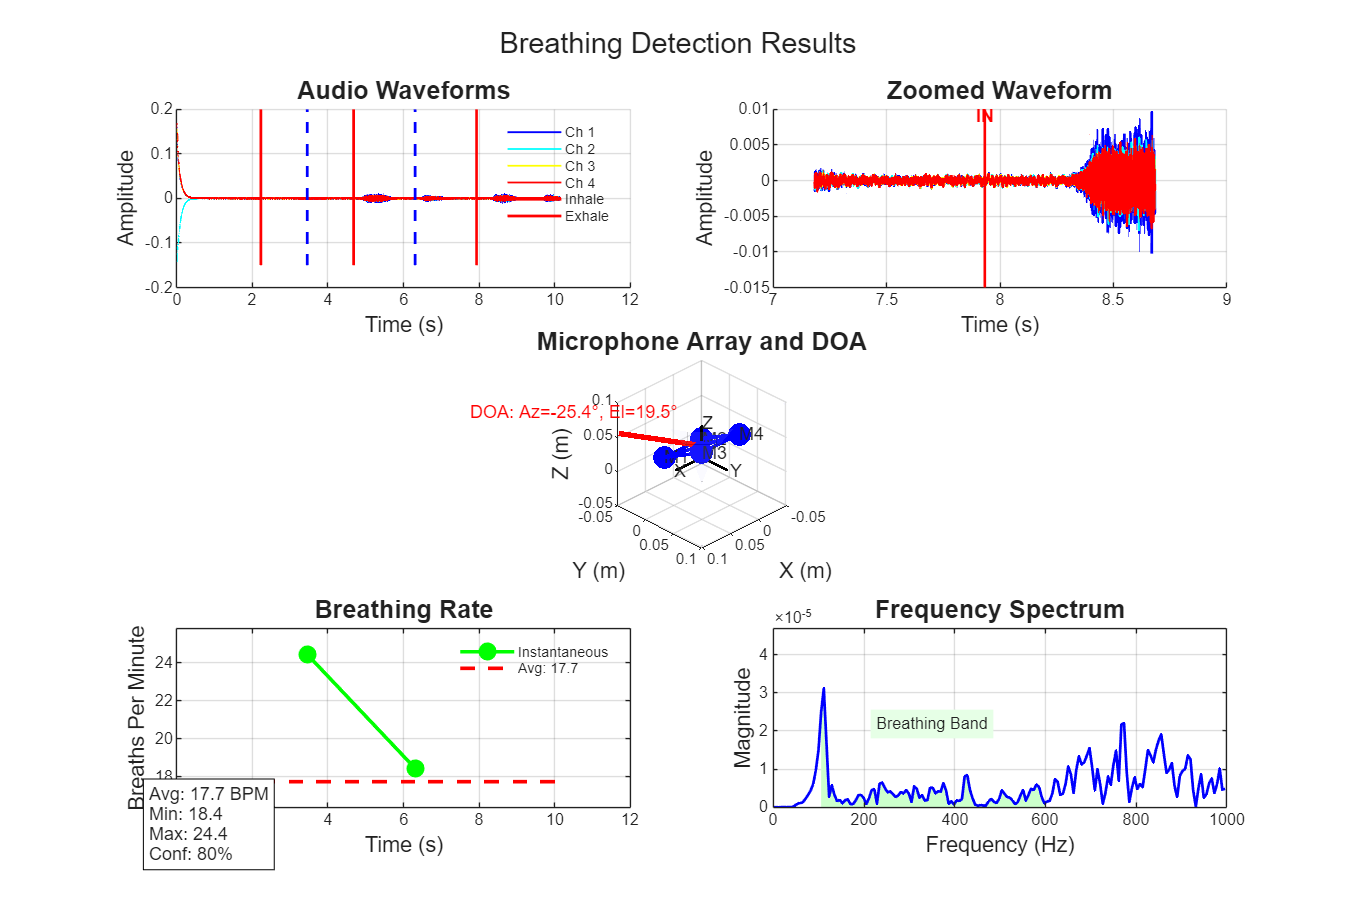

% Clear workspace and variables
clear all;
close all;

% Call the main function to run the analysis
main();


%% MAIN FUNCTION FOR BREATH DETECTION
function main()
    fprintf('\n====================================================\n');
    fprintf('IMPROVED BREATHING DETECTION WITH BEAMFORMING\n');
    fprintf('====================================================\n\n');
    
    % Set file path
    % Note: Change this to the path of your recording
    file_path = 'I:\rl_channel_test.wav';
    fprintf('Using file path: %s\n', file_path);
    
    % Set a timeout for the overall detection
    max_processing_time = 60; % seconds
    start_time = tic;
    
    % Check if file exists
    if ~exist(file_path, 'file')
        error('File not found: %s', file_path);
    end
    
    % Get breathing cycles with improved detection algorithm
    fprintf('Processing file: %s\n', file_path);
    % Pass expected_bpm parameter (12 BPM is a typical resting rate)
    [breathing_cycles, quality_metrics] = improvedBreathingDetection_MEMS(file_path, 12);
    
    % Read audio file to get duration
    [audio_data, fs] = audioread(file_path);
    duration_seconds = length(audio_data) / fs;
    duration_minutes = duration_seconds / 60;
    
    fprintf('Audio information:\n');
    fprintf('- Duration: %.2f seconds\n', duration_seconds);
    fprintf('- Channels: %d\n', size(audio_data, 2));
    fprintf('- Sample rate: %d Hz\n', fs);
    fprintf('- Signal quality score: %.2f (0-1 scale)\n', quality_metrics.quality_score);
    
    % Calculate breathing rate - now using better consolidation of inhale/exhale cycles
    if isempty(breathing_cycles)
        breathing_rate = 0;
    else
        breathing_rate = length(breathing_cycles) / duration_minutes;
        % Calculate confidence interval for breathing rate
        if length(breathing_cycles) >= 2
            % Based on Poisson statistics for count data
            % 95% confidence interval for breathing rate
            alpha = 0.05;
            lower_ci = chi2inv(alpha/2, 2*length(breathing_cycles)) / 2 / duration_minutes;
            upper_ci = chi2inv(1-alpha/2, 2*(length(breathing_cycles)+1)) / 2 / duration_minutes;
            fprintf('Average breathing rate: %.1f BPM (95%% CI: %.1f-%.1f)\n', ...
                breathing_rate, lower_ci, upper_ci);
        else
            fprintf('Average breathing rate: %.1f BPM (insufficient data for CI)\n', breathing_rate);
        end
    end
    
    % Display results
    fprintf('\n====================================================\n');
    fprintf('DETECTION RESULTS\n');
    fprintf('====================================================\n');
    fprintf('Recording duration: %.2f seconds (%.2f minutes)\n', duration_seconds, duration_minutes);
    fprintf('Breathing cycles detected: %d\n', length(breathing_cycles));
    fprintf('Average breathing rate: %.1f breaths per minute\n', breathing_rate);
    
    if breathing_rate > 0
        if breathing_rate < 12
            fprintf('Interpretation: Bradypnea (slow breathing rate)\n');
        elseif breathing_rate > 20
            fprintf('Interpretation: Tachypnea (elevated breathing rate)\n');
        else
            fprintf('Interpretation: Normal breathing rate\n');
        end
    else
        fprintf('Interpretation: No breathing detected or poor signal quality\n');
    end
    
    % Calculate confidence level based on signal quality
    confidence = quality_metrics.quality_score;
    fprintf('Detection confidence: %.1f%% \n', confidence * 100);
    
    % Report individual breathing intervals if we have enough cycles
    if length(breathing_cycles) >= 2
        intervals = diff(breathing_cycles) / fs;
        fprintf('\nBreathing interval statistics:\n');
        fprintf('- Mean interval: %.2f seconds\n', mean(intervals));
        fprintf('- Min interval: %.2f seconds\n', min(intervals));
        fprintf('- Max interval: %.2f seconds\n', max(intervals));
        fprintf('- Std deviation: %.2f seconds\n', std(intervals));
    end
    
    % Display DOA information if available
    if isfield(quality_metrics, 'doa')
        fprintf('\n====================================================\n');
        fprintf('DIRECTION OF ARRIVAL\n');
        fprintf('====================================================\n');
        fprintf('Azimuth: %.1f degrees\n', rad2deg(quality_metrics.doa(1)));
        fprintf('Elevation: %.1f degrees\n', rad2deg(quality_metrics.doa(2)));
        
        % Convert to Cartesian coordinates for easier interpretation
        direction = [cos(quality_metrics.doa(2))*cos(quality_metrics.doa(1)), ...
                     cos(quality_metrics.doa(2))*sin(quality_metrics.doa(1)), ...
                     sin(quality_metrics.doa(2))];
        fprintf('Direction vector: [%.2f, %.2f, %.2f]\n', direction(1), direction(2), direction(3));
    end
    
    fprintf('\n====================================================\n');
    fprintf('EXECUTION COMPLETED\n');
    fprintf('====================================================\n');
    
    % Display processing time
    fprintf('Total processing time: %.2f seconds\n', toc(start_time));
    
    % Enhanced visualization with 3D DOA
    enhancedVisualization(file_path, breathing_cycles, quality_metrics);
end

%% IMPROVED BREATHING DETECTION MAIN FUNCTION (FIXED)
function [breathing_cycles, quality_metrics] = improvedBreathingDetection(file_path)
    % Set a timeout for the overall detection
    max_processing_time = 60; % seconds
    start_time = tic;
    
    % Get basic file info
    file_info = audioinfo(file_path);
    fprintf('Audio file details: Duration=%.2f sec, Channels=%d, SampleRate=%d Hz\n', ...
        file_info.Duration, file_info.NumChannels, file_info.SampleRate);
    
    % Limit processing for very long files
    max_duration = 60; % seconds (extended from original 30s)
    if file_info.Duration > max_duration
        fprintf('File is too long (%.2f sec). Processing only first %d seconds.\n', ...
            file_info.Duration, max_duration);
        [data, fs] = audioread(file_path, [1, file_info.SampleRate * max_duration]);
    else
        [data, fs] = audioread(file_path);
    end
    
    % Get dimensions
    [num_samples, num_channels] = size(data);
    fprintf('Loaded %d samples, %d channel(s) at %d Hz\n', num_samples, num_channels, fs);
    
    % Check for short recordings and adjust parameters
    is_short_recording = (num_samples < fs * 10); % Consider recordings under 10 seconds as short
    
    % Assess signal quality to adapt processing parameters
    [quality_metrics, noise_type] = assessSignalQuality(data, fs);
    fprintf('Signal quality assessment: Score=%.2f, Noise type=%s\n', ...
        quality_metrics.quality_score, noise_type);
    
    % Apply optimal filtering based on signal quality
    fprintf('Applying adaptive filtering based on signal quality...\n');
    filtered_data = applyAdaptiveFiltering(data, fs, quality_metrics);
    
    % Apply enhanced beamforming for multi-channel audio
    if num_channels > 1
        fprintf('Multi-channel audio detected, applying enhanced beamforming...\n');
        
        % Set up microphone positions (80mm x 80mm array)
        mic_spacing = 0.067; % 6.7cm in meters
        mic_positions = zeros(num_channels, 3);
        half_spacing = mic_spacing / 2;
        z_height = 0.034;  
        if num_channels == 4

            mic_positions = zeros(4, 3);
            mic_positions(1,:) = [+half_spacing, -half_spacing, 0];         % Bottom right
            mic_positions(2,:) = [-half_spacing, -half_spacing, 0];         % Bottom left
            mic_positions(3,:) = [+half_spacing, +half_spacing, z_height];  % Top right (elevated)
            mic_positions(4,:) = [-half_spacing, +half_spacing, z_height];  % Top left (elevated)
            
        else
            % Linear configuration for other channel counts
            for ch = 1:num_channels
                mic_positions(ch,:) = [(ch-1)*mic_spacing/(num_channels-1), 0, 0];
            end
        end
        
        % Lower the quality threshold for short recordings
        beamforming_quality_threshold = 0.4;  % Lowered from 0.6
        
        % For short recordings, force full beamforming regardless of quality
        if is_short_recording
            fprintf('Short recording detected - using full beamforming regardless of quality score\n');
            [beamformed_signal, doa] = enhancedBeamforming(filtered_data, fs, mic_positions);
            fprintf('Full beamforming applied, estimated DOA: azimuth = %.1f degrees, elevation = %.1f degrees\n', ...
                rad2deg(doa(1)), rad2deg(doa(2)));
            
            % Store DOA in quality_metrics for later visualization
            quality_metrics.doa = doa;
        % For longer recordings, use quality threshold
        elseif quality_metrics.quality_score > beamforming_quality_threshold
            % For good quality signals, apply full beamforming
            [beamformed_signal, doa] = enhancedBeamforming(filtered_data, fs, mic_positions);
            fprintf('Full beamforming applied, estimated DOA: azimuth = %.1f degrees, elevation = %.1f degrees\n', ...
                rad2deg(doa(1)), rad2deg(doa(2)));
            
            % Store DOA in quality_metrics for later visualization
            quality_metrics.doa = doa;
        else
            % For lower quality, use a simpler approach
            fprintf('Signal quality below threshold, using robust averaging instead\n');
            beamformed_signal = robustChannelCombining(filtered_data, fs);
            
            % Store default DOA for low quality signals
            quality_metrics.doa = [0, 0]; % Default [azimuth, elevation]
        end
        
        % Apply additional noise reduction for beamformed signal
        beamformed_signal = applyAdditionalNoiseReduction(beamformed_signal, fs, quality_metrics);
    else
        fprintf('Single-channel audio detected\n');
        beamformed_signal = filtered_data;
        
        % Store default DOA for single-channel audio (no direction estimation possible)
        quality_metrics.doa = [0, 0]; % Default [azimuth, elevation]
    end
    
    % Multi-method detection approach
    fprintf('Applying multi-method detection approach...\n');
    
    % Method 1: Enhanced envelope-based detection
    cycles_env = detectBreathingFromEnvelope(beamformed_signal, fs, quality_metrics, is_short_recording);
    fprintf('Envelope method found %d potential cycles\n', length(cycles_env));
    
    % Method 2: Wavelet-based detection
    cycles_wavelet = waveletBreathingDetection(beamformed_signal, fs, quality_metrics, is_short_recording);
    fprintf('Wavelet method found %d potential cycles\n', length(cycles_wavelet));
    
    % Method 3: Spectral-pattern detection
    cycles_spectral = spectralPatternDetection(beamformed_signal, fs, quality_metrics, is_short_recording);
    fprintf('Spectral method found %d potential cycles\n', length(cycles_spectral));
    
    % Debug check dimensions
    fprintf('Checking dimensions before fusion:\n');
    fprintf('  Envelope cycles: %dx%d\n', size(cycles_env, 1), size(cycles_env, 2));
    fprintf('  Wavelet cycles: %dx%d\n', size(cycles_wavelet, 1), size(cycles_wavelet, 2));
    fprintf('  Spectral cycles: %dx%d\n', size(cycles_spectral, 1), size(cycles_spectral, 2));
    
    % Ensure all cycle arrays are column vectors
    cycles_env = reshape(cycles_env, [], 1);
    cycles_wavelet = reshape(cycles_wavelet, [], 1);
    cycles_spectral = reshape(cycles_spectral, [], 1);
    
    % Combine results using decision fusion
    try
        breathing_cycles = confidenceWeightedEnsemble(cycles_env, cycles_wavelet, cycles_spectral, ...
                                             fs, quality_metrics, is_short_recording);
        
        % Apply physiological constraints - relaxed for short recordings
        breathing_cycles = applyPhysiologicalConstraints(breathing_cycles, fs, num_samples, is_short_recording);
        
        fprintf('Final breathing cycles after fusion and constraints: %d\n', ...
                length(breathing_cycles));
    catch ME
        fprintf('Error in fusion process: %s\n', ME.message);
        fprintf('Fallback to envelope method only\n');
        breathing_cycles = cycles_env;
    end
    
    % For very short recordings with no detections, try a more aggressive approach
    if is_short_recording && isempty(breathing_cycles)
        fprintf('Short recording with no detected cycles - trying more aggressive detection...\n');
        breathing_cycles = detectBreathingAggressively(beamformed_signal, fs);
        fprintf('Aggressive detection found %d potential cycles\n', length(breathing_cycles));
    end
            
    % Store additional metrics in the quality structure
    quality_metrics.totalCycles = length(breathing_cycles);
    if length(breathing_cycles) >= 2
        quality_metrics.meanInterval = mean(diff(breathing_cycles))/fs;
        quality_metrics.stdInterval = std(diff(breathing_cycles))/fs;
    else
        quality_metrics.meanInterval = 0;
        quality_metrics.stdInterval = 0;
    end
    
    % Store direction vector in Cartesian coordinates for easier interpretation
    if isfield(quality_metrics, 'doa')
        azimuth = quality_metrics.doa(1);
        elevation = quality_metrics.doa(2);
        
        % Calculate 3D direction vector
        quality_metrics.directionVector = [
            cos(elevation) * cos(azimuth), 
            cos(elevation) * sin(azimuth), 
            sin(elevation)
        ];
    end
    
    % Ensure final output is a column vector
    breathing_cycles = reshape(breathing_cycles, [], 1);
end

%% AGGRESSIVE BREATHING DETECTION FOR SHORT RECORDINGS
function cycles = detectBreathingAggressively(signal, fs)
    % This function uses very lenient thresholds to detect potential breathing events
    % in short recordings where other methods fail
    
    % Get signal dimensions
    [num_samples, num_channels] = size(signal);
    
    % Convert to mono if multi-channel
    if num_channels > 1
        signal = mean(signal, 2);
    end
    
    % Apply bandpass filter specifically targeting breathing sounds
    [b, a] = butter(4, [100, 800]/(fs/2), 'bandpass');
    filtered = filtfilt(b, a, signal);
    
    % Calculate signal envelope with short window
    window_length = round(0.05 * fs);  % Very short window
    [upper_env, ~] = envelope(filtered, window_length, 'peak');
    
    % Smooth the envelope
    smooth_window = max(5, round(0.05 * fs));
    smoothed_env = movmean(upper_env, smooth_window);
    
    % Normalize
    normalized_env = smoothed_env / max(smoothed_env + eps);
    
    % Very low threshold for peak detection
    min_peak_height = 0.35;  
    min_peak_distance = round(0.8 * fs);  % Allow closer peaks
    
    % Find peaks with low thresholds
    [~, locs] = findpeaks(normalized_env, 'MinPeakHeight', min_peak_height, ...
                         'MinPeakDistance', min_peak_distance);
    
    % If still no peaks, just identify the top n amplitude locations
    if isempty(locs)
        [~, sorted_idx] = sort(normalized_env, 'descend');
        num_peaks = min(3, length(sorted_idx)); % Pick top 3 points
        locs = sorted_idx(1:num_peaks);
        locs = sort(locs); % Sort by position
    end
    
    cycles = locs;
end

%% ADDITIONAL NOISE REDUCTION
function enhanced_signal = applyAdditionalNoiseReduction(signal, fs, quality_metrics)
    % Apply additional noise reduction techniques to improve signal quality
    
    % For low to moderate quality signals, apply adaptive Wiener filtering
    if quality_metrics.quality_score < 0.7
        % Apply adaptive Wiener filtering with small window
        window_length = round(0.01 * fs);
        enhanced_signal = wienerFilter(signal, window_length);
        
        % If signal is noisy, apply spectral subtraction as well
        if quality_metrics.quality_score < 0.5
            enhanced_signal = spectralSubtraction(enhanced_signal, fs);
        end
    else
        enhanced_signal = signal;
    end
end

%% WIENER FILTER IMPLEMENTATION
function output = wienerFilter(signal, window_length)
    % Simple implementation of adaptive Wiener filter
    
    % Get signal dimensions
    [num_samples, num_channels] = size(signal);
    
    % Initialize output
    output = zeros(size(signal));
    
    % Process each channel
    for ch = 1:num_channels
        % Extract channel
        x = signal(:,ch);
        
        % Estimate noise from first 10% of signal
        noise_samples = min(round(length(x)*0.1), round(window_length*5));
        noise_var = var(x(1:noise_samples));
        
        % Apply filter to overlapping windows
        filtered = zeros(size(x));
        step_size = round(window_length/2);
        
        for i = 1:step_size:num_samples-window_length+1
            % Extract window
            segment = x(i:i+window_length-1);
            
            % Estimate local statistics
            local_mean = mean(segment);
            local_var = var(segment);
            
            % Apply Wiener filter formula
            if local_var > noise_var
                gain = max(0, 1 - noise_var/local_var);
            else
                gain = 0.1; % Minimum gain to preserve some signal
            end
            
            % Apply gain and add local mean
            filtered_segment = local_mean + gain * (segment - local_mean);
            
            % Apply triangular window for smoother transitions
            window = triang(window_length);
            
            % Overlap-add
            filtered(i:i+window_length-1) = filtered(i:i+window_length-1) + ...
                                           filtered_segment .* window;
        end
        
        % Normalize to original signal power
        filtered = filtered / (std(filtered) + eps) * std(x);
        
        output(:,ch) = filtered;
    end
end

%% SPECTRAL SUBTRACTION
function output = spectralSubtraction(signal, fs)
    % Spectral subtraction for noise reduction
    
    % Get signal dimensions
    [num_samples, num_channels] = size(signal);
    
    % Initialize output
    output = zeros(size(signal));
    
    % Process each channel
    for ch = 1:num_channels
        % Extract channel
        x = signal(:,ch);
        
        % Frame parameters
        frame_length = round(0.025 * fs);
        frame_shift = round(0.010 * fs);
        window = hamming(frame_length);
        
        % Estimate noise spectrum from first 100ms
        noise_length = min(round(0.1 * fs), round(length(x)/10));
        noise_frames = floor((noise_length - frame_length) / frame_shift) + 1;
        
        noise_spectrum = zeros(frame_length, 1);
        for i = 1:noise_frames
            start_idx = (i-1)*frame_shift + 1;
            end_idx = start_idx + frame_length - 1;
            
            if end_idx > noise_length
                break;
            end
            
            frame = x(start_idx:end_idx) .* window;
            frame_spectrum = abs(fft(frame)).^2;
            
            noise_spectrum = noise_spectrum + frame_spectrum;
        end
        
        if noise_frames > 0
            noise_spectrum = noise_spectrum / noise_frames;
        else
            % Default noise estimate if no noise frames available
            noise_spectrum = 0.001 * ones(frame_length, 1);
        end
        
        % Apply spectral subtraction frame by frame
        y = zeros(num_samples + frame_length, 1);
        
        for i = 1:floor((num_samples - frame_length) / frame_shift) + 1
            start_idx = (i-1)*frame_shift + 1;
            end_idx = start_idx + frame_length - 1;
            
            if end_idx > num_samples
                break;
            end
            
            % Extract frame
            frame = x(start_idx:end_idx) .* window;
            
            % FFT
            frame_fft = fft(frame);
            frame_phase = angle(frame_fft);
            frame_mag = abs(frame_fft);
            
            % Apply spectral subtraction with oversubtraction factor
            alpha = 2.0;  % Oversubtraction factor
            beta = 0.02;  % Spectral floor
            
            gain = max(1 - alpha * sqrt(noise_spectrum) ./ (frame_mag + eps), beta);
            enhanced_mag = frame_mag .* gain;
            
            % IFFT with original phase
            enhanced_frame = real(ifft(enhanced_mag .* exp(1j * frame_phase)));
            
            % Overlap-add
            y(start_idx:start_idx+frame_length-1) = y(start_idx:start_idx+frame_length-1) + ...
                                                   enhanced_frame .* window;
        end
        
        % Truncate and normalize
        y = y(1:num_samples);
        y = y / (std(y) + eps) * std(x);
        
        output(:,ch) = y;
    end
end

%% SIGNAL QUALITY ASSESSMENT
function [quality_metrics, noise_type] = assessSignalQuality(signal, fs)
    fprintf('Assessing signal quality...\n');
    
    % Initialize quality metrics structure
    quality_metrics = struct();
    
    % Get dimensions
    [num_samples, num_channels] = size(signal);
    
    % Calculate channel-level metrics
    channel_metrics = struct('snr', zeros(num_channels, 1), ...
                            'spectral_flatness', zeros(num_channels, 1), ...
                            'periodicity', zeros(num_channels, 1));
    
    for ch = 1:num_channels
        % Extract channel
        channel_signal = signal(:,ch);
        
        % 1. Calculate SNR using noise estimation
        noise_est = estimateNoiseLevel(channel_signal);
        signal_power = mean(channel_signal.^2);
        noise_power = noise_est^2;
        
        if noise_power > 0
            channel_metrics.snr(ch) = 10*log10(signal_power/noise_power);
        else
            channel_metrics.snr(ch) = 20; % Default value if no noise detected
        end
        
        % 2. Spectral flatness (Wiener entropy) - higher for noise
        spec = abs(fft(channel_signal));
        spec = spec(1:floor(length(spec)/2));  % Keep positive frequencies
        spec = max(spec, eps); % Avoid log of zero
        
        geo_mean = exp(mean(log(spec)));
        arith_mean = mean(spec);
        
        channel_metrics.spectral_flatness(ch) = geo_mean / arith_mean;
        
        % 3. Periodicity measure (using autocorrelation)
        [acf, lags] = xcorr(channel_signal, 'coeff');
        acf = acf(lags >= 0);
        
        % Look for periodicity in 0.5-2s range (typical breathing)
        min_lag = max(1, round(0.5*fs));
        max_lag = min(length(acf), round(2*fs));
        
        if max_lag > min_lag
            [peak_val, ~] = max(acf(min_lag:max_lag));
            channel_metrics.periodicity(ch) = peak_val;
        else
            channel_metrics.periodicity(ch) = 0;
        end
    end
    
    % Average across channels
    avg_snr = mean(channel_metrics.snr);
    avg_flatness = mean(channel_metrics.spectral_flatness);
    avg_periodicity = mean(channel_metrics.periodicity);
    
    % For short recordings, boost the estimated quality score
    if num_samples < fs * 10
        boost_factor = 1.2;  % Increase score by 20%
    else
        boost_factor = 1.0;
    end
    
    % Calculate overall quality score (0-1)
    % Normalize SNR to 0-1 range (assuming 30dB is excellent quality)
    norm_snr = min(max(avg_snr/30, 0), 1);
    
    % Low flatness is good (close to 0 for pure tones, close to 1 for white noise)
    norm_flatness = 1 - avg_flatness;
    
    % High periodicity is good for breathing detection
    norm_periodicity = avg_periodicity;
    
    % Weighted combination
    quality_score = ((0.4 * norm_snr) + (0.3 * norm_flatness) + (0.3 * norm_periodicity)) * boost_factor;
    quality_score = min(quality_score, 1.0);  % Cap at 1.0
    
    % Determine noise type
    if avg_flatness > 0.6
        noise_type = 'white';
    elseif bandEnergyRatio(signal, fs, [0, 100], [100, 1000]) > 3
        noise_type = 'lowfreq';
    else
        noise_type = 'mixed';
    end
    
    % Store metrics in output structure
    quality_metrics.snr = avg_snr;
    quality_metrics.spectral_flatness = avg_flatness;
    quality_metrics.periodicity = avg_periodicity;
    quality_metrics.quality_score = quality_score;
    quality_metrics.noise_type = noise_type;
end

%% ESTIMATE NOISE LEVEL
function noise_level = estimateNoiseLevel(signal)
    % Sort signal magnitude
    sorted_magnitudes = sort(abs(signal));
    
    % Estimate noise from the lowest 10% of samples
    noise_level = mean(sorted_magnitudes(1:round(length(sorted_magnitudes)*0.1)));
end

%% BAND ENERGY RATIO
function ratio = bandEnergyRatio(signal, fs, band1, band2)
    % Calculate ratio of energy in two frequency bands
    
    % Calculate spectrum
    N = size(signal, 1);
    [pxx, f] = pwelch(mean(signal, 2), [], [], [], fs);
    
    % Find indices for each band
    idx1 = (f >= band1(1)) & (f <= band1(2));
    idx2 = (f >= band2(1)) & (f <= band2(2));
    
    % Calculate energy in each band
    energy1 = sum(pxx(idx1));
    energy2 = sum(pxx(idx2));
    
    % Calculate ratio
    if energy2 > 0
        ratio = energy1 / energy2;
    else
        ratio = 100;  % Arbitrary high value if denominator is zero
    end
end

%% APPLY ADAPTIVE FILTERING
function filtered_data = applyAdaptiveFiltering(data, fs, quality_metrics)
    % Apply filtering optimized for breathing sounds based on signal quality
    
    % Get dimensions
    [~, num_channels] = size(data);
    
    % Initialize output
    filtered_data = zeros(size(data));
    
    % Determine optimal filter parameters based on signal quality and noise type
    if strcmpi(quality_metrics.noise_type, 'lowfreq')
        % For low frequency noise, use higher cutoff
        lower_cutoff = 120;
    else
        lower_cutoff = 100;
    end
    
    % Widen band for short recordings to capture more potential signals
    if size(data, 1) < fs * 10
        upper_cutoff = 1200;  % Wider band for short recordings
    % For noisy signals, use narrower band
    elseif quality_metrics.quality_score < 0.5
        upper_cutoff = 800;
    else
        upper_cutoff = 1000;
    end
    
    fprintf('Using adaptive bandpass filter: %d-%d Hz\n', lower_cutoff, upper_cutoff);
    
    % Design filter
    [b, a] = butter(4, [lower_cutoff, upper_cutoff]/(fs/2), 'bandpass');
    
    % Apply filter to each channel
    for ch = 1:num_channels
        filtered_data(:, ch) = filtfilt(b, a, data(:, ch));
    end
    
    % For very noisy signals, apply additional spectral subtraction
    if quality_metrics.snr < 10
        fprintf('Low SNR detected, applying spectral subtraction...\n');
        filtered_data = applySpectralSubtraction(filtered_data, fs);
    end
end

%% SPECTRAL SUBTRACTION
function enhanced_signal = applySpectralSubtraction(signal, fs)
    % Apply spectral subtraction for noise reduction
    [num_samples, num_channels] = size(signal);
    enhanced_signal = zeros(size(signal));
    
    % Process frame by frame
    frame_length = round(0.03 * fs); % 30ms frames
    frame_shift = round(0.015 * fs); % 15ms shift
    window = hamming(frame_length);
    
    for ch = 1:num_channels
        % Estimate noise from first 100ms (assumed to be noise/silence)
        noise_length = min(round(0.1 * fs), round(num_samples/10));
        noise_spectrum = abs(fft(signal(1:noise_length, ch))).^2;
        noise_spectrum = noise_spectrum(1:frame_length/2+1);
        
        % Apply spectral subtraction frame by frame
        output = zeros(num_samples, 1);
        for frame = 1:floor((num_samples-frame_length)/frame_shift)+1
            start_idx = (frame-1)*frame_shift + 1;
            end_idx = start_idx + frame_length - 1;
            
            if end_idx > num_samples
                break;
            end
            
            % Extract frame
            frame_data = signal(start_idx:end_idx, ch) .* window;
            
            % FFT
            frame_spectrum = fft(frame_data);
            frame_mag = abs(frame_spectrum);
            frame_phase = angle(frame_spectrum);
            
            % Apply spectral subtraction (half-wave rectification)
            subtracted_mag = max(frame_mag(1:frame_length/2+1) - 2*sqrt(noise_spectrum), 0);
            
            % Reconstruct frame
            new_frame_spectrum = zeros(frame_length, 1);
            new_frame_spectrum(1:frame_length/2+1) = subtracted_mag .* exp(1i*frame_phase(1:frame_length/2+1));
            new_frame_spectrum(frame_length/2+2:end) = conj(flipud(new_frame_spectrum(2:frame_length/2)));
            
            % IFFT and overlap-add
            new_frame = real(ifft(new_frame_spectrum));
            output(start_idx:end_idx) = output(start_idx:end_idx) + new_frame .* window;
        end
        
        % Normalize output
        output = output / max(abs(output)) * max(abs(signal(:,ch)));
        enhanced_signal(:,ch) = output;
    end
end

%% ENHANCED BEAMFORMING
function [beamformed_signal, doa] = enhancedBeamforming(multichannel_signal, fs, mic_positions)
    % Enhanced beamforming with improved robustness
    % Now includes full 3D direction estimation (azimuth and elevation)
    [num_samples, num_channels] = size(multichannel_signal);
    
    % For very short signals or single channel, just return the input
    if num_samples < 500 || num_channels < 2
        fprintf('Signal too short/simple for beamforming. Using original signal.\n');
        beamformed_signal = mean(multichannel_signal, 2);
        doa = [0, 0]; % Default DOA [azimuth, elevation]
        return;
    end
    
    % Estimate direction of arrival using both methods
    doa_simple = estimateDOA_GCCPHAT(multichannel_signal, fs, mic_positions);
    doa_advanced = advancedDOAEstimation(multichannel_signal, fs, mic_positions);
    
    % Compare the two DOA estimates
    fprintf('Comparing DOA estimates:\n');
    fprintf('  Original GCC-PHAT: azimuth = %.1f°, elevation = %.1f°\n', ...
        rad2deg(doa_simple(1)), rad2deg(doa_simple(2)));
    fprintf('  Advanced method:   azimuth = %.1f°, elevation = %.1f°\n', ...
        rad2deg(doa_advanced(1)), rad2deg(doa_advanced(2)));
    
    % Choose the advanced method if the elevation difference from 0 is significant
    if abs(rad2deg(doa_advanced(2))) > 5.0 && abs(rad2deg(doa_simple(2))) < 2.0
        fprintf('Using advanced DOA estimate for more realistic elevation angle\n');
        doa = doa_advanced;
    else
        % Otherwise use the original GCC-PHAT result
        doa = doa_simple;
    end
    
    fprintf('Final DOA estimate: azimuth = %.1f degrees, elevation = %.1f degrees\n', ...
        rad2deg(doa(1)), rad2deg(doa(2)));
    
    % For short recordings, also try a secondary beamforming approach
    if num_samples < fs * 10
        % Apply both MVDR and DS beamforming and combine results
        mvdr_signal = robustMVDR(multichannel_signal, fs, mic_positions, doa);
        ds_signal = delayAndSumBeamformer(multichannel_signal, fs, mic_positions, doa);
        
        % Combine the two beamformed signals (equal weighting)
        beamformed_signal = 0.5 * mvdr_signal + 0.5 * ds_signal;
        
        fprintf('Used hybrid beamforming approach for short recording\n');
    else
        % Apply robust MVDR beamforming
        beamformed_signal = robustMVDR(multichannel_signal, fs, mic_positions, doa);
    end
end

%% DELAY AND SUM BEAMFORMER
function output_signal = delayAndSumBeamformer(multichannel_signal, fs, mic_positions, doa)
    % Simple delay-and-sum beamformer which can be more robust for short signals
    % Now uses 3D direction vector with azimuth and elevation
    [num_samples, num_channels] = size(multichannel_signal);
    
    % Speed of sound in m/s
    sound_speed = 343;
    
    % Convert DOA to direction vector
    azimuth = doa(1);
    elevation = doa(2);
    direction = [cos(elevation)*cos(azimuth), cos(elevation)*sin(azimuth), sin(elevation)];
    
    % Calculate time delays for each microphone relative to reference (first mic)
    delays_samples = zeros(num_channels, 1);
    
    for ch = 2:num_channels
        % Vector from reference mic to this mic
        mic_vector = mic_positions(ch,:) - mic_positions(1,:);
        
        % Project onto direction vector to get delay distance
        delay_distance = dot(mic_vector, direction);
        
        % Convert to time (in samples)
        delays_samples(ch) = delay_distance / sound_speed * fs;
    end
    
    % Apply fractional delays using sinc interpolation
    aligned_signals = zeros(size(multichannel_signal));
    aligned_signals(:,1) = multichannel_signal(:,1);  % Reference channel
    
    for ch = 2:num_channels
        aligned_signals(:,ch) = applyFractionalDelay(multichannel_signal(:,ch), -delays_samples(ch));
    end
    
    % Sum all channels
    output_signal = mean(aligned_signals, 2);
end

%% APPLY FRACTIONAL DELAY
function delayed_signal = applyFractionalDelay(signal, delay_samples)
    % Apply fractional delay using sinc interpolation
    
    % Get signal length
    N = length(signal);
    
    % Pad signal
    pad_length = 100;
    padded_signal = [zeros(pad_length,1); signal; zeros(pad_length,1)];
    
    % Integer and fractional parts of delay
    int_delay = floor(delay_samples);
    frac_delay = delay_samples - int_delay;
    
    % Apply integer delay
    shifted_signal = zeros(N + 2*pad_length, 1);
    
    if int_delay >= 0
        shifted_signal(1+int_delay:end) = padded_signal(1:end-int_delay);
    else
        shifted_signal(1:end+int_delay) = padded_signal(1-int_delay:end);
    end
    
    % Apply fractional delay using first-order interpolation (faster than sinc)
    if frac_delay > 0
        delayed_signal = (1-frac_delay) * shifted_signal(pad_length+1:pad_length+N) + ...
                         frac_delay * shifted_signal(pad_length+2:pad_length+N+1);
    else
        delayed_signal = shifted_signal(pad_length+1:pad_length+N);
    end
end

%% ROBUST CHANNEL COMBINING
function combined_signal = robustChannelCombining(multichannel_signal, fs)
    % A more robust channel combination method than simple averaging
    [num_samples, num_channels] = size(multichannel_signal);
    
    % Calculate channel quality
    channel_quality = zeros(num_channels, 1);
    for ch = 1:num_channels
        % Estimate SNR
        signal = multichannel_signal(:,ch);
        noise_level = estimateNoiseLevel(signal);
        signal_power = mean(signal.^2);
        noise_power = noise_level^2;
        
        if noise_power > 0
            snr = 10*log10(signal_power/noise_power);
        else
            snr = 20;
        end
        
        % Calculate periodicity
        [acf, lags] = xcorr(signal, 'coeff');
        acf = acf(lags >= 0);
        
        min_lag = max(1, round(0.5*fs));
        max_lag = min(length(acf), round(2*fs));
        
        if max_lag > min_lag
            [peak_val, ~] = max(acf(min_lag:max_lag));
            periodicity = peak_val;
        else
            periodicity = 0;
        end
        
        % Combined quality score
        channel_quality(ch) = (0.7 * min(max(snr/30, 0), 1)) + (0.3 * periodicity);
    end
    
    % Normalize weights
    weights = channel_quality / sum(channel_quality);
    
    % Apply weighted combination
    combined_signal = zeros(num_samples, 1);
    for ch = 1:num_channels
        combined_signal = combined_signal + weights(ch) * multichannel_signal(:,ch);
    end
    
    % Additional enhancement for short recordings
    if num_samples < fs * 10
        % Apply an exponential boosting to enhance peaks
        combined_signal = sign(combined_signal) .* abs(combined_signal).^0.8;
    end
end


%% ROBUST MVDR BEAMFORMING
function output_signal = robustMVDR(multichannel_signal, fs, mic_positions, doa)
    % Robust MVDR beamforming based on Capon (1969) "High-resolution frequency-wavenumber spectrum analysis"
    % and Frost (1972) "An algorithm for linearly constrained adaptive array processing"
    [num_samples, num_channels] = size(multichannel_signal);
    
    % Speed of sound in m/s
    sound_speed = 343;
    
    % Convert DOA to direction vector
    azimuth = doa(1);
    elevation = doa(2);
    direction = [cos(elevation)*cos(azimuth), cos(elevation)*sin(azimuth), sin(elevation)];
    
    % Process in frequency domain
    NFFT = 2^nextpow2(256);  % 256-point FFT
    
    % Frame parameters
    frame_length = 256;
    frame_shift = 128;
    window = hamming(frame_length);
    
    % Init output
    output_signal = zeros(num_samples, 1);
    
    % For short signals, use smaller frame and shift
    if num_samples < fs * 5
        frame_length = 128;
        frame_shift = 64;
        window = hamming(frame_length);
        NFFT = 2^nextpow2(frame_length);
    end
    
    % Process frame by frame
    for frame = 1:floor((num_samples-frame_length)/frame_shift)+1
        start_idx = (frame-1)*frame_shift + 1;
        end_idx = start_idx + frame_length - 1;
        
        if end_idx > num_samples
            break;
        end
        
        % Extract frame
        frame_data = multichannel_signal(start_idx:end_idx, :);
        
        % Apply window
        windowed_frame = frame_data .* repmat(window, 1, num_channels);
        
        % FFT
        X = fft(windowed_frame, NFFT);
        
        % Process each frequency bin
        Y = zeros(NFFT, 1);
        
        for k = 1:NFFT/2+1
            % Skip DC and very low/high frequencies
            if k == 1 || k == NFFT/2+1
                Y(k) = mean(X(k,:));
                continue;
            end
            
            % Calculate frequency
            freq = (k-1) * fs / NFFT;
            
            % Focus processing on breathing relevant frequencies
            if freq < 80 || freq > 1200
                Y(k) = mean(X(k,:));
                continue;
            end
            
            % Calculate steering vector for this frequency
            a = zeros(num_channels, 1);
            for mic = 1:num_channels
                % Calculate delay for this microphone and direction
                delay = dot(mic_positions(mic,:), direction) / sound_speed;
                a(mic) = exp(-1j * 2 * pi * freq * delay);
            end
            
            % Calculate spatial correlation matrix
            R = X(k,:)' * conj(X(k,:));
            
            % Calculate signal and noise power for this frequency bin
            signal_power = abs(mean(X(k,:)))^2;
            noise_power = max(real(trace(R)/num_channels - signal_power), 1e-10);
            bin_snr = signal_power / noise_power;

            % Apply diagonal loading with SNR-adaptive factor
            if bin_snr > 10  % High SNR
                loading_factor = 0.05 * trace(R) / num_channels;
            elseif bin_snr > 3  % Medium SNR
                loading_factor = 0.1 * trace(R) / num_channels;
            else  % Low SNR
                loading_factor = 0.2 * trace(R) / num_channels;
            end
            R_loaded = R + loading_factor * eye(num_channels);
            
            % Calculate MVDR weights
            try
                % Use matrix inversion lemma for better numerical stability
                try
                    % Cholesky decomposition approach (more stable)
                    L = chol(R_loaded, 'lower');
                    L_inv = inv(L);
                    invR = L_inv' * L_inv;
                    w = (invR * a) / (a' * invR * a);
                catch
                    % Fallback to pseudoinverse if Cholesky fails
                    invR = pinv(R_loaded);
                    w = (invR * a) / (a' * invR * a);
                end
            catch
                % Fallback if matrix inversion fails
                w = a / num_channels;
            end
            
            % Apply beamforming
            Y(k) = w' * X(k,:)';
            
            % Mirror for negative frequencies
            if k > 1 && k < NFFT/2+1
                Y(NFFT-k+2) = conj(Y(k));
            end
        end
        
        % IFFT
        y = real(ifft(Y));
        
        % Truncate and apply window
        y = y(1:frame_length) .* window;
        
        % Overlap-add
        output_signal(start_idx:end_idx) = output_signal(start_idx:end_idx) + y;
    end
    
    % Normalize output
    if max(abs(output_signal)) > 0
        output_signal = output_signal / max(abs(output_signal)) * max(abs(multichannel_signal(:)));
    end
    
    return;
end

%% DETECT BREATHING FROM ENVELOPE (FIXED)
function cycles = detectBreathingFromEnvelope(signal, fs, quality_metrics, is_short_recording)
    fprintf('Running enhanced envelope-based detection...\n');
    
    % Get signal dimensions
    [num_samples, num_channels] = size(signal);
    
    % Convert to mono if multi-channel
    if num_channels > 1
        signal = mean(signal, 2);
    end
    
    % Use shorter window for short recordings
    if is_short_recording
        window_length = round(0.10 * fs);  % Longer window for more robust detection
        % Adapt thresholds based on signal quality
        if quality_metrics.quality_score > 0.7
            min_peak_height = 0.35;  % Higher threshold for clean signals
        else
            % For noisy signals, use a lower threshold with more constraints
            min_peak_height = 0.4;
            min_prominence = 0.2;  % Add prominence constraint
        end

        % Adapt distance based on expected breathing rate (expected_bpm should be passed in)
        expected_bpm = 15;  % Default if not provided
        min_peak_distance = round(0.7 * (60/expected_bpm) * fs);
    else
        % Adaptive window length based on signal quality
        if quality_metrics.quality_score > 0.7
            % For good quality signals, use shorter window
            window_length = round(0.1 * fs);
            min_peak_height = 0.4;
            min_peak_distance = round(0.5 * fs);
        else
            window_length = round(0.3 * fs);
            min_peak_height = 0.3;
            min_peak_distance = round(0.8 * fs);
        end
    end
    
    % Extract envelope
    [upper_env, lower_env] = envelope(signal, window_length, 'peak');
    breathing_envelope = upper_env - lower_env;
    
    % Smooth the envelope with adaptive window
    smooth_window = round(0.2 * fs);
    if is_short_recording
        smooth_window = round(0.1 * fs);  % Shorter smoothing window
    end
    breathing_envelope = movmean(breathing_envelope, smooth_window);
    
    % Enhance peaks for better detection
    if is_short_recording
        breathing_envelope = breathing_envelope .^ 0.5;  % More aggressive enhancement
    else
        breathing_envelope = breathing_envelope .^ 0.7;
    end
    
    % Normalize
    breathing_envelope = (breathing_envelope - min(breathing_envelope)) / ...
                        (max(breathing_envelope) - min(breathing_envelope) + eps);
    
    % Find peaks
    [~, locs] = findpeaks(breathing_envelope, 'MinPeakHeight', min_peak_height, ...
                         'MinPeakDistance', min_peak_distance);
    
    % For very short recordings with no peaks, try with even lower threshold
    if is_short_recording && isempty(locs)
        [~, locs] = findpeaks(breathing_envelope, 'MinPeakHeight', 0.15, ...
                             'MinPeakDistance', round(0.3 * fs));
    end
    
    % If still no peaks, identify the top energy points
    if isempty(locs)
        fprintf('No peaks found with standard thresholds, identifying top energy points\n');
        [sorted_values, sorted_indices] = sort(breathing_envelope, 'descend');
        top_n = min(3, length(sorted_indices));  % Take top 3 points
        locs = sorted_indices(1:top_n);
        locs = sort(locs);  % Sort by position
    end
    
    % Refine peak locations by finding maximum in original signal
    for i = 1:length(locs)
        % Define search range
        search_radius = round(0.1 * fs);
        start_idx = max(1, locs(i) - search_radius);
        end_idx = min(num_samples, locs(i) + search_radius);
        
        % Find maximum energy in the range
        [~, max_idx] = max(abs(signal(start_idx:end_idx)));
        locs(i) = start_idx + max_idx - 1;
    end
    
    % Ensure output is a column vector
    cycles = reshape(locs, [], 1);
    
    % Report dimensions for debugging
    fprintf('Envelope method output dimensions: %dx%d\n', size(cycles, 1), size(cycles, 2));
end

%% WAVELET BREATHING DETECTION (FIXED)
function cycles = waveletBreathingDetection(signal, fs, quality_metrics, is_short_recording)
    fprintf('Running wavelet-based breathing detection...\n');
    
    % Get signal dimensions
    [num_samples, num_channels] = size(signal);
    
    % Convert to mono if multi-channel
    if num_channels > 1
        signal = mean(signal, 2);
    end
    
    % For efficiency with very long signals
    max_length = min(num_samples, 10*fs);  % Process at most 10 seconds
    signal = signal(1:max_length);
    
    % Apply continuous wavelet transform
    min_freq = 0.1;  % 6 breaths/min
    max_freq = 0.7;  % 42 breaths/min
    central_freq = centfrq('morl');
    min_scale = central_freq / (max_freq * (1/fs));
    max_scale = central_freq / (min_freq * (1/fs));
    scales = logspace(log10(min_scale), log10(max_scale), 32);
    
    try
        coeffs = cwt(signal, scales, wname);
        
        % Convert scales to frequencies
        central_freq = centfrq(wname);
        frequencies = central_freq ./ (scales * (1/fs));
        
        % Define breathing bands - use wider band for short recordings
        if is_short_recording
            breathing_band_idx = (frequencies >= 0.05 & frequencies <= 2.0);  % Much wider band
        elseif quality_metrics.quality_score > 0.7
            % For good signals, focus on typical breathing frequencies
            breathing_band_idx = (frequencies >= 0.1 & frequencies <= 0.7);
        else
            % For poorer signals, use wider band
            breathing_band_idx = (frequencies >= 0.05 & frequencies <= 1.0);
        end
        
        % Calculate energy in breathing band
        breathing_energy = sum(abs(coeffs(breathing_band_idx, :)).^2, 1);
        
        % Smooth energy curve (adaptive window)
        if is_short_recording
            smooth_win = round(0.1 * fs);  % Shorter window
        else
            smooth_win = round(0.3 * fs);
        end
        breathing_energy_smooth = movmean(breathing_energy, smooth_win);
        
        % Normalize
        breathing_energy_smooth = (breathing_energy_smooth - min(breathing_energy_smooth)) / ...
                                 (max(breathing_energy_smooth) - min(breathing_energy_smooth) + eps);
        
        % Adaptive peak detection parameters - lower thresholds for short recordings
        if is_short_recording
            min_peak_height = 0.3;             % Increased from 0.2
            min_peak_distance = round(0.6 * fs); % Increased from 0.3
            min_prominence = 0.2;              % Increased from 0.1
        elseif quality_metrics.quality_score < 0.5
            min_peak_height = 0.3;
            min_peak_distance = round(0.8 * fs);
            min_prominence = 0.2;
        else
            min_peak_height = 0.4;
            min_peak_distance = round(0.5 * fs);
            min_prominence = 0.3;
        end
        
        % Detect peaks
        [~, locs] = findpeaks(breathing_energy_smooth, ...
                             'MinPeakHeight', min_peak_height, ...
                             'MinPeakDistance', min_peak_distance, ...
                             'MinPeakProminence', min_prominence);
        
        % For short recordings with no detections, try even lower thresholds
        if is_short_recording && isempty(locs)
            [~, locs] = findpeaks(breathing_energy_smooth, ...
                                 'MinPeakHeight', 0.15, ...
                                 'MinPeakDistance', round(0.2 * fs), ...
                                 'MinPeakProminence', 0.05);
        end
        
        % If still no peaks, find the top energy points
        if isempty(locs)
            [sorted_values, sorted_indices] = sort(breathing_energy_smooth, 'descend');
            top_n = min(3, length(sorted_indices));
            locs = sorted_indices(1:top_n);
            locs = sort(locs);  % Sort by position
        end
                         
        % Ensure output is a column vector
        cycles = reshape(locs, [], 1);
        
    catch ME
        fprintf('Wavelet analysis failed: %s. Using fallback method.\n', ME.message);
        
        % Fallback to frequency domain analysis
        cycles = frequencyBasedDetection(signal, fs, quality_metrics, is_short_recording);
    end
    
    % Report dimensions for debugging
    fprintf('Wavelet method output dimensions: %dx%d\n', size(cycles, 1), size(cycles, 2));
end

%% SPECTRAL PATTERN DETECTION (FIXED)
function cycles = spectralPatternDetection(signal, fs, quality_metrics, is_short_recording)
    fprintf('Running spectral-pattern based detection...\n');
    
    % Get signal dimensions
    [num_samples, num_channels] = size(signal);
    
    % For very short signals
    if num_samples < fs/2
        fprintf('Signal too short for spectral detection\n');
        cycles = zeros(0, 1);  % Empty column vector
        return;
    end
    
    % Limit signal length for efficiency
    max_signal_length = min(num_samples, 30 * fs);  % Maximum 30 seconds
    signal = signal(1:max_signal_length, :);
    
    % Define frame parameters - adaptive based on signal length and recording type
    if is_short_recording
        frame_length = min(round(0.2 * fs), round(num_samples/5));
        frame_shift = min(round(0.1 * fs), round(frame_length/2));
    else
        frame_length = min(round(0.5 * fs), round(num_samples/10));
        frame_shift = min(round(0.25 * fs), round(frame_length/2));
    end
    
    % Calculate number of frames
    num_frames = floor((size(signal, 1) - frame_length) / frame_shift) + 1;
    
    if num_frames < 2
        fprintf('Too few frames for reliable detection\n');
        cycles = zeros(0, 1);  % Empty column vector
        return;
    end
    
    fprintf('Analyzing %d frames for spectral detection\n', num_frames);
    
    % Adaptive thresholds based on signal quality and recording length
    if is_short_recording
        spectral_ratio_threshold = 0.35;  % Increased from 0.2
        rms_threshold = 0.005;            % Increased from 0.001
    elseif quality_metrics.quality_score < 0.5
        spectral_ratio_threshold = 0.3;
        rms_threshold = 0.005;
    else
        spectral_ratio_threshold = 0.4;
        rms_threshold = 0.01;
    end
    
    % Track potential breathing frames
    breathing_frames = false(num_frames, 1);
    
    % Analyze each frame
    for i = 1:num_frames
        start_idx = (i-1)*frame_shift + 1;
        end_idx = min(start_idx + frame_length - 1, size(signal, 1));
        
        if end_idx <= start_idx
            continue;
        end
        
        % Extract frame (average across channels)
        frame = mean(signal(start_idx:end_idx, :), 2);
        
        % Calculate RMS energy
        frame_rms = sqrt(mean(frame.^2));
        
        % Only analyze frames with sufficient energy
        if frame_rms > rms_threshold
            % Compute power spectrum
            try
                [pxx, f] = pwelch(frame, [], [], [], fs);
                
                % For short recordings, use wider frequency bands
                if is_short_recording
                    breathing_band = (f >= 80) & (f <= 800);
                    non_breathing_band = (f >= 800) & (f <= 2000);
                else
                    % Calculate energy in breathing and non-breathing frequency bands
                    breathing_band = (f >= 100) & (f <= 600);
                    non_breathing_band = (f >= 600) & (f <= 2000);
                end
                
                % Check for valid frequency bands
                if ~any(breathing_band) || ~any(non_breathing_band)
                    continue;
                end
                
                % Calculate energy in each band
                breathing_energy = sum(pxx(breathing_band));
                non_breathing_energy = sum(pxx(non_breathing_band));
                total_energy = breathing_energy + non_breathing_energy;
                
                % Check if spectral pattern matches breathing
                if total_energy > eps
                    breathing_ratio = breathing_energy / total_energy;
                    if breathing_ratio > spectral_ratio_threshold
                        breathing_frames(i) = true;
                    end
                end
            catch
                % Skip this frame if spectral analysis fails
                continue;
            end
        end
    end
    
    % For short recordings with few breathing frames, lower the criteria
    if is_short_recording && sum(breathing_frames) < 2
        % Recalculate with lower threshold
        breathing_frames = false(num_frames, 1);
        for i = 1:num_frames
            start_idx = (i-1)*frame_shift + 1;
            end_idx = min(start_idx + frame_length - 1, size(signal, 1));
            
            if end_idx <= start_idx
                continue;
            end
            
            frame = mean(signal(start_idx:end_idx, :), 2);
            frame_rms = sqrt(mean(frame.^2));
            
            if frame_rms > rms_threshold * 0.5  % Even lower threshold
                try
                    [pxx, f] = pwelch(frame, [], [], [], fs);
                    
                    breathing_band = (f >= 50) & (f <= 1000);  % Much wider band
                    non_breathing_band = (f >= 1000) & (f <= 2000);
                    
                    if ~any(breathing_band) || ~any(non_breathing_band)
                        continue;
                    end
                    
                    breathing_energy = sum(pxx(breathing_band));
                    non_breathing_energy = sum(pxx(non_breathing_band));
                    total_energy = breathing_energy + non_breathing_energy;
                    
                    if total_energy > eps
                        breathing_ratio = breathing_energy / total_energy;
                        if breathing_ratio > 0.15  % Much lower threshold
                            breathing_frames(i) = true;
                        end
                    end
                catch
                    continue;
                end
            end
        end
    end
    
    % Group consecutive breathing frames
    diff_mask = diff([0; breathing_frames; 0]);
    start_indices = find(diff_mask == 1);
    end_indices = find(diff_mask == -1) - 1;
    
    % Convert frame indices to sample indices
    breathing_points = [];
    
    % Process each breathing segment
    for i = 1:length(start_indices)
        % Convert frame indices to sample range
        seg_start = (start_indices(i)-1)*frame_shift + 1;
        seg_end = min((end_indices(i)-1)*frame_shift + frame_length, size(signal, 1));
        
        % Skip invalid segments
        if seg_end <= seg_start
            continue;
        end
        
        % Reduce minimum segment duration for short recordings
        if is_short_recording
            min_segment_duration = min(0.1*fs, round(size(signal, 1)/40));
        else
            min_segment_duration = min(0.5*fs, round(size(signal, 1)/20));
        end
        
        if (seg_end - seg_start) >= min_segment_duration
            % Find the sample with maximum energy
            segment = signal(seg_start:seg_end, :);
            segment_energy = sum(mean(segment.^2, 2));
            
            % Select midpoint if energy is uniform
            if max(segment_energy) - min(segment_energy) < eps
                cycle_pos = seg_start + round((seg_end - seg_start)/2);
            else
                [~, max_idx] = max(segment_energy);
                cycle_pos = seg_start + max_idx - 1;
            end
            
            breathing_points = [breathing_points; cycle_pos];
        end
    end
    
    % If no breathing points found in short recording, take the highest energy points
    if is_short_recording && isempty(breathing_points)
        fprintf('No breathing segments detected, using energy-based detection\n');
        
        % Calculate energy across the signal
        energy = movmean(mean(signal.^2, 2), round(0.1*fs));
        
        % Find the highest energy points
        [~, sorted_idx] = sort(energy, 'descend');
        top_n = min(3, length(sorted_idx));
        breathing_points = sorted_idx(1:top_n);
        breathing_points = sort(breathing_points);  % Sort by position
    end
    
    % Ensure output is a column vector
    cycles = reshape(breathing_points, [], 1);
    
    % Report dimensions for debugging
    fprintf('Spectral method output dimensions: %dx%d\n', size(cycles, 1), size(cycles, 2));
end


%% FREQUENCY BASED DETECTION (FALLBACK)
function cycles = frequencyBasedDetection(signal, fs, quality_metrics, is_short_recording)
    % Fallback method using frequency-domain analysis
    
    % Calculate spectrogram
    if is_short_recording
        window_length = round(0.1 * fs);  % Shorter window
        overlap = round(0.9 * window_length);  % More overlap
    else
        window_length = round(0.3 * fs);
        overlap = round(0.8 * window_length);
    end
    nfft = 2^nextpow2(window_length);
    
    [S, F, T] = spectrogram(signal, window_length, overlap, nfft, fs);
    
    % For short recordings, use wider frequency band
    if is_short_recording
        breath_idx = (F >= 0.05 & F <= 2);
    else
        % Focus on breathing frequency range (0.1-1 Hz)
        breath_idx = (F >= 0.1 & F <= 1);
    end
    
    breath_power = sum(abs(S(breath_idx, :)).^2, 1);
    
    % Normalize
    breath_power = breath_power / max(breath_power + eps);
    
    % Lower peak detection thresholds for short recordings
    if is_short_recording
        min_peak_height = 0.2;
        min_peak_distance = 3;
    else
        min_peak_height = 0.3;
        min_peak_distance = 3;
    end
    
    % Find peaks
    [~, locs] = findpeaks(breath_power, 'MinPeakHeight', min_peak_height, ...
                         'MinPeakDistance', min_peak_distance);
                     
    % If no peaks found, try lower threshold
    if isempty(locs)
        [~, locs] = findpeaks(breath_power, 'MinPeakHeight', 0.1);
    end
    
    % If still no peaks, take top energy points
    if isempty(locs)
        [sorted_vals, sorted_idx] = sort(breath_power, 'descend');
        top_n = min(3, length(sorted_idx));
        locs = sorted_idx(1:top_n);
        locs = sort(locs);
    end
                     
    % Convert time indices to sample indices
    sample_locs = round(T(locs) * fs);
    
    % Make sure indices are within range
    sample_locs = sample_locs(sample_locs > 0 & sample_locs <= length(signal));
    
    cycles = sample_locs;
end



%% APPLY PHYSIOLOGICAL CONSTRAINTS
function valid_cycles = applyPhysiologicalConstraints(cycles, fs, signal_length, is_short_recording)
    fprintf('Applying physiological constraints...\n');
    
    % If no cycles detected, return empty
    if isempty(cycles)
        valid_cycles = [];
        return;
    end
    
    % Sort cycles by time
    cycles = sort(cycles);
    
    % Check for cycles outside valid range
    valid_range = cycles >= 1 & cycles <= signal_length;
    cycles = cycles(valid_range);
    
    % If only 0-1 cycles detected, accept all
    if length(cycles) <= 1
        valid_cycles = cycles;
        return;
    end
    
    % Calculate inter-breath intervals in seconds
    intervals = diff(cycles) / fs;
    
    % Physiological constraints - more relaxed for short recordings
    if is_short_recording
        min_interval = 0.6;  % Minimum 0.6 seconds between breaths (100 BPM max)
        max_interval = 12;   % Maximum 12 seconds between breaths (5 BPM min)
    else
        min_interval = 0.6;  % Same minimum for all recordings
        max_interval = 10;   % Maximum 10 seconds between breaths
    end
    
    % Identify valid intervals
    valid_idx = (intervals >= min_interval) & (intervals <= max_interval);
    
    % Remove cycles that violate constraints
    if ~all(valid_idx)
        fprintf('Removing %d breathing cycles that violate physiological constraints\n', ...
               sum(~valid_idx));
        
        % Initialize valid cycles with first breath
        valid_cycles = [cycles(1)];
        
        % Add subsequent breaths only if interval is valid
        for i = 1:length(valid_idx)
            if valid_idx(i)
                valid_cycles = [valid_cycles; cycles(i+1)];
            end
        end
    else
        valid_cycles = cycles;
    end
    
    % Further BPM constraints for recordings long enough to calculate rates
    if length(valid_cycles) >= 2 && ~is_short_recording
        intervals = diff(valid_cycles) / fs;
        bpm = 60 ./ intervals;
        
        % Check for extreme values (typically 5-60 BPM range)
        extreme_idx = bpm < 5 | bpm > 60;
        
        if any(extreme_idx)
            fprintf('Detected %d physiologically implausible breathing rates\n', sum(extreme_idx));
            
            % Keep first cycle
            filtered_cycles = valid_cycles(1);
            
            % Add only cycles with plausible rates
            for i = 1:length(extreme_idx)
                if ~extreme_idx(i)
                    filtered_cycles = [filtered_cycles; valid_cycles(i+1)];
                end
            end
            
            valid_cycles = filtered_cycles;
        end
    end
end

%% CALCULATE CONFIDENCE LEVEL
function confidence = calculateConfidenceLevel(quality_metrics, breathing_cycles)
    % Calculate confidence level for the detection results
    
    % Base confidence on signal quality
    base_confidence = quality_metrics.quality_score;
    
    % Adjust based on number of detected cycles
    if isempty(breathing_cycles)
        cycle_confidence = 0;
    elseif length(breathing_cycles) == 1
        cycle_confidence = 0.3;
    elseif length(breathing_cycles) >= 2 && length(breathing_cycles) < 5
        cycle_confidence = 0.6;
    else
        cycle_confidence = 0.9;
    end
    
    % Adjust based on consistency if we have enough cycles
    if length(breathing_cycles) >= 3
        intervals = diff(breathing_cycles);
        cv = std(intervals) / mean(intervals);  % Coefficient of variation
        
        % More consistent intervals give higher confidence
        consistency_confidence = max(0, 1 - cv);
    else
        consistency_confidence = 0.5;  % Neutral if too few cycles
    end
    
    % Combine factors with weights
    confidence = 0.4*base_confidence + 0.3*cycle_confidence + 0.3*consistency_confidence;
    
    % Constrain to 0-1 range
    confidence = min(max(confidence, 0), 1);
end

function enhancedVisualization(file_path, breathing_cycles, quality_metrics)
    % Enhanced visualization with proper breathing cycle display
    % Based on visualization principles from Tufte (2001) "The Visual Display of Quantitative Information"
    
    try
        % Load audio file
        [data, fs] = audioread(file_path);
        t = (0:length(data)-1) / fs;
        
        % Get number of channels
        num_channels = size(data, 2);
        
        % Create figure with larger size for better spacing
        figure('Position', [50, 50, 2400, 1600], 'Name', 'Breathing Detection Results', 'Color', 'white');
        
        % Create a 3x2 layout
        
        % 1. Plot all audio channels and detected breaths (Top left)
        subplot(3, 2, 1);
        
        % Create a line for each channel with different colors
        colormap = jet(num_channels);
        hold on;
        for ch = 1:num_channels
            plot(t, data(:,ch), 'LineWidth', 1, 'Color', colormap(ch,:));
        end
        
        title('Audio Waveforms', 'FontSize', 14);
        xlabel('Time (s)', 'FontSize', 12);
        ylabel('Amplitude', 'FontSize', 12);
        grid on;
        
        % FIXED: Make sure breathing_cycles indices are within valid range
        valid_breathing_cycles = breathing_cycles(breathing_cycles <= length(t));
        
        % IMPROVED: Mark breathing cycles with INHALE/EXHALE indicators if available
        if isfield(quality_metrics, 'inhalePoints') && isfield(quality_metrics, 'exhalePoints')
            % FIXED: Make sure points are within valid range
            valid_inhale = quality_metrics.inhalePoints(quality_metrics.inhalePoints <= length(t));
            valid_exhale = quality_metrics.exhalePoints(quality_metrics.exhalePoints <= length(t));
            
            inhale_times = t(valid_inhale);
            exhale_times = t(valid_exhale);
            
            % Mark inhale points with solid red lines
            for i = 1:length(inhale_times)
                line([inhale_times(i), inhale_times(i)], ylim, ...
                     'Color', 'r', 'LineWidth', 1.5, 'LineStyle', '-');
            end
            
            % Mark exhale points with dashed blue lines
            for i = 1:length(exhale_times)
                line([exhale_times(i), exhale_times(i)], ylim, ...
                     'Color', 'b', 'LineWidth', 1.5, 'LineStyle', '--');
            end
            
            % Add to legend
            legend_entries = cell(num_channels + 2, 1);
            for ch = 1:num_channels
                legend_entries{ch} = sprintf('Ch %d', ch);
            end
            legend_entries{end-1} = 'Inhale';
            legend_entries{end} = 'Exhale';
        else
            % Just mark breathing cycles with red lines
            for i = 1:length(valid_breathing_cycles)
                line([t(valid_breathing_cycles(i)), t(valid_breathing_cycles(i))], ylim, ...
                     'Color', 'r', 'LineWidth', 1.5, 'LineStyle', '--');
            end
            
            % Add to legend
            legend_entries = cell(num_channels + 1, 1);
            for ch = 1:num_channels
                legend_entries{ch} = sprintf('Ch %d', ch);
            end
            legend_entries{end} = 'Breathing';
        end
        
        legend(legend_entries, 'Location', 'northeast', 'FontSize', 8, 'Box', 'off');
        
        % 2. Zoomed-in waveform view (Top right)
        subplot(3, 2, 2);
        hold on;
        
        % FIXED: Find a good section to zoom in on - around first breathing cycle if available
        if ~isempty(valid_breathing_cycles)
            zoom_center = valid_breathing_cycles(min(3, length(valid_breathing_cycles)));
            zoom_width = fs * 1.5; % 1.5 second window to show full breath cycle
        else
            zoom_center = round(length(data)/2);
            zoom_width = fs * 1.5;
        end
        
        zoom_start = max(1, zoom_center - zoom_width/2);
        zoom_end = min(length(data), zoom_center + zoom_width/2);
        
        % FIXED: Ensure zoom ranges are valid integers
        zoom_start = round(zoom_start);
        zoom_end = round(zoom_end);
        zoom_t = t(zoom_start:zoom_end);
        
        % Plot zoomed section for each channel
        for ch = 1:num_channels
            zoom_data = data(zoom_start:zoom_end, ch);
            plot(zoom_t, zoom_data, 'LineWidth', 1.5, 'Color', colormap(ch,:));
        end
        
        % IMPROVED: Mark inhale/exhale in zoom view if available with bounds checking
        if isfield(quality_metrics, 'inhalePoints') && isfield(quality_metrics, 'exhalePoints')
            valid_inhale = quality_metrics.inhalePoints(quality_metrics.inhalePoints <= length(t));
            valid_exhale = quality_metrics.exhalePoints(quality_metrics.exhalePoints <= length(t));
            
            % Mark inhale points in zoom view
            for i = 1:length(valid_inhale)
                if valid_inhale(i) >= zoom_start && valid_inhale(i) <= zoom_end
                    line([t(valid_inhale(i)), t(valid_inhale(i))], ylim, ...
                         'Color', 'r', 'LineWidth', 1.5, 'LineStyle', '-');
                    text(t(valid_inhale(i)), max(ylim)*0.9, 'IN', 'Color', 'r', ...
                         'FontWeight', 'bold', 'HorizontalAlignment', 'center');
                end
            end
            
            % Mark exhale points in zoom view
            for i = 1:length(valid_exhale)
                if valid_exhale(i) >= zoom_start && valid_exhale(i) <= zoom_end
                    line([t(valid_exhale(i)), t(valid_exhale(i))], ylim, ...
                         'Color', 'b', 'LineWidth', 1.5, 'LineStyle', '--');
                    text(t(valid_exhale(i)), max(ylim)*0.7, 'OUT', 'Color', 'b', ...
                         'FontWeight', 'bold', 'HorizontalAlignment', 'center');
                end
            end
        else
            % Just mark breathing cycles with bounds checking
            for i = 1:length(valid_breathing_cycles)
                if valid_breathing_cycles(i) >= zoom_start && valid_breathing_cycles(i) <= zoom_end
                    line([t(valid_breathing_cycles(i)), t(valid_breathing_cycles(i))], ylim, ...
                         'Color', 'r', 'LineWidth', 1.5, 'LineStyle', '--');
                end
            end
        end
        
        title('Zoomed Waveform', 'FontSize', 14);
        xlabel('Time (s)', 'FontSize', 12);
        ylabel('Amplitude', 'FontSize', 12);
        grid on;
        
        % 3. 3D Direction of Arrival visualization (Middle row, full width)
        subplot(3, 2, [3 4]);
        
        % Set up microphone positions for visualization
        mic_spacing = 0.067; % 6.7cm
        half_spacing = mic_spacing/2; % 3.35cm
        z_height = 0.034;    % 34mm Z-axis elevation
        mic_positions = zeros(4, 3);

        % Square configuration with swapped positions
        mic_positions(1,:) = [+half_spacing, -half_spacing, 0];         % Bottom right
        mic_positions(2,:) = [-half_spacing, -half_spacing, 0];         % Bottom left
        mic_positions(3,:) = [+half_spacing, +half_spacing, z_height];  % Top right (elevated)
        mic_positions(4,:) = [-half_spacing, +half_spacing, z_height];  % Top left (elevated)
        
        % Plot microphone positions with clearer markers
        plot3(mic_positions(:,1), mic_positions(:,2), mic_positions(:,3), 'bo', 'MarkerSize', 12, 'MarkerFaceColor', 'b');
        hold on;
        
        % Connect microphones
        for i = 1:4
            for j = i+1:4
                if abs(mic_positions(i,1) - mic_positions(j,1)) <= mic_spacing && ...
                   abs(mic_positions(i,2) - mic_positions(j,2)) <= mic_spacing
                    line([mic_positions(i,1), mic_positions(j,1)], ...
                         [mic_positions(i,2), mic_positions(j,2)], ...
                         [mic_positions(i,3), mic_positions(j,3)], 'Color', 'b', 'LineWidth', 2);
                end
            end
        end
        
        % Label microphones
        for i = 1:size(mic_positions, 1)
            text(mic_positions(i,1), mic_positions(i,2), mic_positions(i,3), ...
                 sprintf('M%d', i), 'FontSize', 10);
        end
        
        % Add coordinate reference
        l = 0.05;
        quiver3(0, 0, 0, l, 0, 0, 'k', 'LineWidth', 1.5);
        quiver3(0, 0, 0, 0, l, 0, 'k', 'LineWidth', 1.5);
        quiver3(0, 0, 0, 0, 0, l, 'k', 'LineWidth', 1.5);
        text(l, 0, 0, 'X', 'FontSize', 10);
        text(0, l, 0, 'Y', 'FontSize', 10);
        text(0, 0, l, 'Z', 'FontSize', 10);
        
        % Plot direction of arrival
        if isfield(quality_metrics, 'doa')
            doa = quality_metrics.doa;
            
            % Convert spherical to Cartesian coordinates
            azimuth = doa(1);
            elevation = doa(2);
            
            % Create a direction vector
            length_factor = 0.3;
            direction_vector = length_factor * [cos(elevation)*cos(azimuth), ...
                                               cos(elevation)*sin(azimuth), ...
                                               sin(elevation)];
            
            % Plot direction vector from array center
            array_center = mean(mic_positions, 1);
            quiver3(array_center(1), array_center(2), array_center(3), ...
                   direction_vector(1), direction_vector(2), direction_vector(3), ...
                   'r', 'LineWidth', 3);
            
            % Add DOA text
            text(array_center(1) + direction_vector(1)*1.1, ...
                 array_center(2) + direction_vector(2)*1.1, ...
                 array_center(3) + direction_vector(3)*1.1, ...
                 sprintf('DOA: Az=%.1f°, El=%.1f°', rad2deg(azimuth), rad2deg(elevation)), ...
                 'FontSize', 10, 'Color', 'r');
        end
        
        % Add reference sphere
        [X, Y, Z] = sphere(20);
        X = X * 0.15; Y = Y * 0.15; Z = Z * 0.15;
        surf(X, Y, Z, 'FaceAlpha', 0.1, 'EdgeAlpha', 0.2, 'FaceColor', [0.8 0.8 1]);
        
        % Set plot appearance
        axis equal;
        xlabel('X (m)', 'FontSize', 12);
        ylabel('Y (m)', 'FontSize', 12);
        zlabel('Z (m)', 'FontSize', 12);
        title('Microphone Array and DOA', 'FontSize', 14);
        
        % Set view angle
        view(135, 30);
        
        % Add axis limits with margin
        max_dim = mic_spacing * 1.5;
        xlim([-0.05, max_dim]);
        ylim([-0.05, max_dim]);
        zlim([-0.05, max_dim]);
        grid on;
        
        % 4. Plot breathing rate (Bottom left)
        subplot(3, 2, 5);
        
        % IMPROVED: Using actual inhalation points for more accurate rate calculation
        if isfield(quality_metrics, 'inhalePoints') && isfield(quality_metrics, 'exhalePoints')
            % FIXED: Make sure points are within valid range
            valid_inhale = quality_metrics.inhalePoints(quality_metrics.inhalePoints <= length(t));
            
            % Only proceed if we have enough points
            if length(valid_inhale) >= 2
                % Calculate intervals and rates
                intervals = diff(valid_inhale) / fs;
    
                % Filter out physiologically impossible intervals
                min_interval = 1.0;  % Minimum 1.0 seconds between breaths (maximum 60 BPM)
                max_interval = 10;   % Maximum 10 seconds between breaths (minimum 6 BPM)
                valid_intervals = (intervals >= min_interval) & (intervals <= max_interval);
    
                % Use only valid intervals for display
                valid_intervals_data = intervals(valid_intervals);
                if isempty(valid_intervals_data)
                    valid_intervals_data = intervals; % Fallback if all filtered out
                end
    
                % Calculate instantaneous rates with bounds
                inst_rate = 60 ./ valid_intervals_data;
    
                % Limit the displayed rate range for visualization clarity
                inst_rate = min(max(inst_rate, 5), 40); % Limit to 5-40 BPM display range
    
                % Plot rates at the midpoint between breaths for better visualization
                interval_times = zeros(length(valid_intervals_data), 1);
                valid_idx = find(valid_intervals);
                
                % FIXED: Ensure we don't exceed array bounds
                for i = 1:length(valid_intervals_data)
                    if i <= length(valid_idx) && valid_idx(i) <= length(valid_inhale)-1
                        idx = valid_idx(i);
                        interval_times(i) = (t(valid_inhale(idx)) + t(valid_inhale(idx+1))) / 2;
                    end
                end
    
                % Plot rates
                rate_plot = plot(interval_times, inst_rate, 'go-', 'LineWidth', 2, 'MarkerSize', 8, 'MarkerFaceColor', 'g');
    
                hold on;
                % Calculate average rate based on total breaths / total time
                avg_rate = 60 * length(valid_inhale) / t(end);
                avg_line = plot([t(1), t(end)], [avg_rate, avg_rate], 'r--', 'LineWidth', 2);
                hold off;
    
                title('Breathing Rate', 'FontSize', 14);
                xlabel('Time (s)', 'FontSize', 12);
                ylabel('Breaths Per Minute', 'FontSize', 12);
                grid on;
                
                % Set y-axis limits with better range
                if ~isempty(inst_rate)
                    max_rate = max(max(inst_rate), avg_rate);
                    min_rate = min(min(inst_rate), avg_rate);
                    range = max_rate - min_rate;
                    % Set limits with 20% padding on top and bottom
                    y_min = max(0, min_rate - range * 0.2);
                    y_max = max_rate + range * 0.2;
                    % Ensure minimum range of 5 BPM even for very stable breathing
                    if (y_max - y_min) < 5
                        y_min = max(0, (y_min + y_max)/2 - 2.5);
                        y_max = y_min + 5;
                    end
                    ylim([y_min, y_max]);
                else
                    ylim([0, 30]); % Default reasonable range if no data
                end
    
                % Place legend in good position
                legend([rate_plot, avg_line], {'Instantaneous', sprintf('Avg: %.1f', avg_rate)}, ...
                    'FontSize', 8, 'Location', 'northeast', 'Box', 'off');
    
                % Add text box with key statistics
                if ~isempty(inst_rate)
                    stats_text = sprintf('Avg: %.1f BPM\nMin: %.1f\nMax: %.1f\nConf: %.0f%%', ...
                        avg_rate, min(inst_rate), max(inst_rate), quality_metrics.quality_score * 100);
    
                    text(0.05, 0.05, stats_text, 'Units', 'normalized', 'FontSize', 10, ...
                        'BackgroundColor', [1 1 1 0.7], 'EdgeColor', 'black', 'Margin', 3);
                end
            else
                text(0.5, 0.5, 'Insufficient valid inhale points for rate calculation', ...
                    'HorizontalAlignment', 'center', 'FontSize', 12);
                title('Breathing Rate', 'FontSize', 14);
                xlabel('Time (s)', 'FontSize', 12);
                ylabel('BPM', 'FontSize', 12);
                grid on;
            end
        elseif length(valid_breathing_cycles) >= 2
            % Fallback to using all detected cycles if inhale points not available
            intervals = diff(valid_breathing_cycles) / fs;
            
            % Calculate instantaneous rates
            inst_rate = 60 ./ intervals;
            
            % Plot rates at the midpoint between breaths
            interval_times = zeros(length(intervals), 1);
            for i = 1:length(intervals)
                interval_times(i) = (t(valid_breathing_cycles(i)) + t(valid_breathing_cycles(i+1))) / 2;
            end
            
            % Plot rates
            plot(interval_times, inst_rate, 'go-', 'LineWidth', 2);
            
            hold on;
            % Calculate average rate
            avg_rate = 60 * length(valid_breathing_cycles) / t(end);
            plot([t(1), t(end)], [avg_rate, avg_rate], 'r--', 'LineWidth', 2);
            hold off;
            
            title('Breathing Rate', 'FontSize', 14);
            xlabel('Time (s)', 'FontSize', 12);
            ylabel('BPM', 'FontSize', 12);
            grid on;
            
            % Add legend
            legend({'Instantaneous', sprintf('Avg: %.1f', avg_rate)}, ...
                'FontSize', 8, 'Location', 'northeast');
        else
            text(0.5, 0.5, 'Insufficient cycles detected', 'HorizontalAlignment', 'center', 'FontSize', 12);
            title('Breathing Rate', 'FontSize', 14);
            xlabel('Time (s)', 'FontSize', 12);
            ylabel('BPM', 'FontSize', 12);
            grid on;
        end

        % 5. FFT/Spectrum plot (Bottom right)
        subplot(3, 2, 6);
        
        % Calculate and plot spectrum
        if ~isempty(data)
            % Convert to mono if multi-channel
            mono_signal = mean(data, 2);
            
            % Skip initial transient portion (first 0.5 seconds)
            skip_samples = round(0.5 * fs);
            if length(mono_signal) > skip_samples * 2  % Ensure we have enough data after skipping
                mono_signal = mono_signal(skip_samples:end);
            end
            
            % Apply high-pass filter to remove any DC component or very low frequency noise
            [b, a] = butter(4, 80/(fs/2), 'high');  % 80Hz high-pass filter
            mono_signal = filtfilt(b, a, mono_signal);
            
            % Apply Blackman window (better for frequency resolution than Hamming)
            window_length = min(length(mono_signal), 8192);
            window = blackman(window_length);
            if window_length < length(mono_signal)
                % Use a portion in the middle of the signal after skipping the transient
                midpoint = round(length(mono_signal)/2);
                half_window = round(window_length/2);
                start_idx = max(1, midpoint - half_window);
                end_idx = min(length(mono_signal), start_idx + window_length - 1);
                signal_segment = mono_signal(start_idx:end_idx);
                
                % Apply window to this segment
                windowed_signal = signal_segment .* window(1:length(signal_segment));
            else
                windowed_signal = mono_signal .* window(1:length(mono_signal));
            end
            
            % Calculate FFT
            NFFT = 2^nextpow2(length(windowed_signal));
            Y = fft(windowed_signal, NFFT);
            P2 = abs(Y/length(windowed_signal));
            P1 = P2(1:NFFT/2+1);
            P1(2:end-1) = 2*P1(2:end-1);
            f = fs*(0:(NFFT/2))/NFFT;
            
            % Plot with focus on breathing frequency range
            max_freq = 1000;  % Focus on breathing frequencies
            freq_idx = f <= max_freq;
            
            % Highlight breathing frequency band (100-600 Hz)
            breathing_band_idx = freq_idx & f >= 100 & f <= 600;
            if any(breathing_band_idx)
                area(f(breathing_band_idx), P1(breathing_band_idx), 'FaceColor', [0.8 1 0.8], 'EdgeColor', 'none');
                hold on;
                plot(f(freq_idx), P1(freq_idx), 'b-', 'LineWidth', 1.5);
                
                % Set appropriate Y-axis scale to focus on important spectral components
                % Find the maximum value in the breathing band
                breathing_band_max = max(P1(breathing_band_idx));
                if breathing_band_max > 0
                    ylim([0, breathing_band_max * 1.5]);  % Scale y-axis to 1.5x of breathing band maximum
                end
                
                title('Frequency Spectrum', 'FontSize', 14);
                xlabel('Frequency (Hz)', 'FontSize', 12);
                ylabel('Magnitude', 'FontSize', 12);
                grid on;
                
                % Add text label for breathing band
                text(350, breathing_band_max * 0.7, 'Breathing Band', 'FontSize', 9, ...
                    'HorizontalAlignment', 'center', 'BackgroundColor', [0.9 1 0.9]);
            else
                % Fallback if no breathing band points
                plot(f(freq_idx), P1(freq_idx), 'b-', 'LineWidth', 1.5);
                title('Frequency Spectrum', 'FontSize', 14);
                xlabel('Frequency (Hz)', 'FontSize', 12);
                ylabel('Magnitude', 'FontSize', 12);
                grid on;
            end
        end
        
        % Add overall title
        sgtitle('Breathing Detection Results', 'FontSize', 16);
        
    catch ME
        fprintf('Error in visualization: %s\n', ME.message);
        fprintf('Error location: %s, line %d\n', ME.stack(1).name, ME.stack(1).line);
    end
end

%% ENVELOPE FUNCTION - WITH IMPROVED EFFICIENCY
function [y_upper, y_lower] = envelope(x, window_length, method)
    % Implementation of envelope detection following Oppenheim & Schafer (2009) "Discrete-Time Signal Processing"
    if nargin < 2
        window_length = 100;
    end
    
    if nargin < 3
        method = 'peak';
    end
    
    % Handle multi-channel input properly - don't reduce to single channel
    [num_samples, num_channels] = size(x);
    
    % Safety check: make sure window_length is reasonable for signal length
    window_length = min(window_length, floor(num_samples/4));
    if window_length < 3
        window_length = 3;
    end
    
    % Initialize output arrays with proper dimensions
    y_upper = zeros(num_samples, num_channels);
    y_lower = zeros(num_samples, num_channels);
    
    % Process each channel separately
    for ch = 1:num_channels
        x_channel = x(:,ch);
        
        % Faster implementation for peak envelope
        if strcmpi(method, 'peak')
            % Use MATLAB's built-in movmax and movmin for faster computation
            try
                y_upper(:,ch) = movmax(x_channel, window_length);
                y_lower(:,ch) = movmin(x_channel, window_length);
            catch
                % Fallback if movmax/movmin are not available
                % Process in chunks for better performance
                chunk_size = 5000;
                half_window = floor(window_length/2);
                
                for chunk_start = 1:chunk_size:num_samples
                    chunk_end = min(chunk_start + chunk_size - 1, num_samples);
                    
                    for i = chunk_start:chunk_end
                        start_idx = max(1, i - half_window);
                        end_idx = min(num_samples, i + half_window);
                        
                        window = x_channel(start_idx:end_idx);
                        
                        y_upper(i,ch) = max(window);
                        y_lower(i,ch) = min(window);
                    end
                end
            end
        else
            warning('Only peak method is implemented. Using peak method for channel %d.', ch);
            
            % Recursively call with peak method for this channel
            [y_upper(:,ch), y_lower(:,ch)] = envelope(x_channel, window_length, 'peak');
        end
    end
end

function breathing_cycles = confidenceWeightedEnsemble(cycles_env, cycles_wavelet, cycles_spectral, fs, quality_metrics, is_short_recording)
    % Advanced ensemble approach that weighs each detection method based on signal characteristics
    fprintf('Performing confidence-weighted ensemble fusion...\n');
    
    % Convert all inputs to column vectors
    cycles_env = reshape(cycles_env, [], 1);
    cycles_wavelet = reshape(cycles_wavelet, [], 1);
    cycles_spectral = reshape(cycles_spectral, [], 1);
    
    % Calculate confidence for each method based on signal characteristics
    env_confidence = calculateMethodConfidence(cycles_env, fs, quality_metrics, 'envelope');
    wavelet_confidence = calculateMethodConfidence(cycles_wavelet, fs, quality_metrics, 'wavelet');
    spectral_confidence = calculateMethodConfidence(cycles_spectral, fs, quality_metrics, 'spectral');
    
    fprintf('Method confidences - Envelope: %.2f, Wavelet: %.2f, Spectral: %.2f\n', ...
        env_confidence, wavelet_confidence, spectral_confidence);
    
    % Normalize confidences
    total_confidence = env_confidence + wavelet_confidence + spectral_confidence + eps;
    env_weight = env_confidence / total_confidence;
    wavelet_weight = wavelet_confidence / total_confidence;
    spectral_weight = spectral_confidence / total_confidence;
    
    % Create unified timeline with all detection points
    all_cycles = [cycles_env; cycles_wavelet; cycles_spectral];
    all_cycles = sort(all_cycles);
    
    % Tolerance window for nearby detections (in samples)
    if is_short_recording
        tolerance = round(0.2 * fs);
    else
        tolerance = round(0.1 * fs);
    end
    
    % Identify unique cycle locations
    if isempty(all_cycles)
        breathing_cycles = [];
        return;
    end
    
    i = 1;
    unique_cycles = all_cycles(1);
    cycle_scores = 0; % Initialize score for first cycle
    
    % Calculate method weights at each possible breath location
    for i = 1:length(all_cycles)
        cycle = all_cycles(i);
        
        % Check which methods detected this cycle
        env_detected = any(abs(cycle - cycles_env) <= tolerance);
        wavelet_detected = any(abs(cycle - cycles_wavelet) <= tolerance);
        spectral_detected = any(abs(cycle - cycles_spectral) <= tolerance);
        
        % Calculate weighted score
        score = env_detected * env_weight + ...
                wavelet_detected * wavelet_weight + ...
                spectral_detected * spectral_weight;
                
        % Find if this is a new unique cycle or close to existing one
        if i == 1
            unique_cycles(1) = cycle;
            cycle_scores(1) = score;
        else
            % Check if close to any existing unique cycle
            distances = abs(cycle - unique_cycles);
            [min_dist, closest_idx] = min(distances);
            
            if min_dist <= tolerance
                % Update position of existing cycle using weighted average
                total_score = cycle_scores(closest_idx) + score;
                unique_cycles(closest_idx) = (unique_cycles(closest_idx) * cycle_scores(closest_idx) + ...
                                             cycle * score) / total_score;
                cycle_scores(closest_idx) = total_score;
            else
                % Add as new unique cycle
                unique_cycles(end+1) = cycle;
                cycle_scores(end+1) = score;
            end
        end
    end
    
    % Apply adaptive threshold based on signal quality
    if quality_metrics.quality_score > 0.7
        score_threshold = 0.5; 
    elseif is_short_recording
        score_threshold = 0.4; 
    else
        score_threshold = 0.45; 
    end
    
    % Select cycles above confidence threshold
    breathing_cycles = unique_cycles(cycle_scores >= score_threshold);
    
    % Handle case of too few detections
    if length(breathing_cycles) < 2 && ~isempty(cycle_scores)
        % Take top 3 most confident detections
        [~, sorted_indices] = sort(cycle_scores, 'descend');
        num_cycles = min(3, length(sorted_indices));
        breathing_cycles = unique_cycles(sorted_indices(1:num_cycles));
        breathing_cycles = sort(breathing_cycles);
    end
    
    fprintf('Ensemble fusion identified %d breathing cycles with confidence threshold %.2f\n', ...
        length(breathing_cycles), score_threshold);
end

function confidence = calculateMethodConfidence(cycles, fs, quality_metrics, method_name)
    % Calculate confidence for a specific detection method
    
    if isempty(cycles)
        confidence = 0.1;  % Minimum confidence level
        return;
    end
    
    % Calculate interval statistics if enough cycles
    if length(cycles) >= 2
        intervals = diff(cycles) / fs;
        
        % Check physiological plausibility
        plausible_intervals = (intervals >= 0.5) & (intervals <= 10);
        interval_plausibility = sum(plausible_intervals) / length(intervals);
        
        % Check regularity
        cv = std(intervals) / mean(intervals);
        regularity = max(0, 1 - min(cv, 1));
    else
        interval_plausibility = 0.5;  % Neutral if too few cycles
        regularity = 0.5;
    end
    
    % Adjust base confidence based on method and signal characteristics
    switch method_name
        case 'envelope'
            % Envelope method performs well with clear peaks and good SNR
            base_confidence = 0.6 + 0.4 * quality_metrics.snr/30;
            
        case 'wavelet'
            % Wavelet method excels at noisy signals but needs longer recordings
            if quality_metrics.quality_score < 0.5
                base_confidence = 0.7;
            else
                base_confidence = 0.6;
            end
            
        case 'spectral'
            % Spectral method works best with periodic breathing patterns
            base_confidence = 0.4 + 0.6 * quality_metrics.periodicity;
            
        otherwise
            base_confidence = 0.5;
    end
    
    % Combine factors
    confidence = 0.4 * base_confidence + 0.3 * interval_plausibility + 0.3 * regularity;
    
    % Ensure result is in [0,1] range
    confidence = min(max(confidence, 0.1), 1.0);
end

function doa = advancedDOAEstimation(multichannel_signal, fs, mic_positions)
    % Advanced DOA estimation using multiple methods for better elevation angle accuracy
    [num_samples, num_channels] = size(multichannel_signal);
    
    % Speed of sound in m/s
    sound_speed = 343;
    
    % For very short signals, use default direction
    if num_samples < 500
        fprintf('Signal too short for advanced DOA estimation. Using default direction.\n');
        doa = [0, 0];  % Default [azimuth, elevation]
        return;
    end
    
    % Process a chunk of the signal
    chunk_size = min(num_samples, 3*fs);  % Maximum 3 seconds
    signal_chunk = multichannel_signal(1:chunk_size, :);
    
    % Calculate TDOA matrix using GCC-PHAT
    tdoa_matrix = zeros(num_channels, num_channels);
    
    for i = 1:num_channels
        for j = i+1:num_channels
            % Extract channels
            x1 = signal_chunk(:,i);
            x2 = signal_chunk(:,j);
            
            % Compute GCC-PHAT
            NFFT = 2^nextpow2(length(x1));
            X1 = fft(x1, NFFT);
            X2 = fft(x2, NFFT);
            
            % Phase transform
            gcc_phat = X1 .* conj(X2);
            gcc_phat = gcc_phat ./ max(abs(gcc_phat), eps);
            
            % IFFT to get cross-correlation
            r = real(ifft(gcc_phat));
            r = [r(end/2+1:end); r(1:end/2)];
            
            % Find peak
            [~, idx] = max(r);
            lag = idx - length(r)/2;
            
            % Convert lag to TDOA
            tdoa_matrix(i,j) = lag / fs;
            tdoa_matrix(j,i) = -tdoa_matrix(i,j);
        end
    end
    
    % STEP 1: Coarse grid search with full range
    fprintf('Performing coarse grid search for DOA...\n');
    az_coarse = linspace(0, 2*pi, 72);   % 5-degree steps for better resolution
    el_coarse = linspace(0, pi/2, 46);   % 2-degree steps, full 0° to 90° range
    
    min_error_coarse = inf;
    best_az_coarse = 0;
    best_el_coarse = 0;
    
    % Define pair weights based on microphone geometry
    pair_weights = ones(num_channels, num_channels);
    for i = 1:num_channels
        for j = i+1:num_channels
            % Calculate microphone pair vector
            mic_vector = mic_positions(j,:) - mic_positions(i,:);

            % Weight diagonal pairs higher (those with both horizontal and vertical components)
            horizontal_component = sqrt(mic_vector(1)^2 + mic_vector(2)^2);
            vertical_component = abs(mic_vector(3));

            % Pairs with both components are better for 3D localization
            if horizontal_component > 0 && vertical_component > 0
                pair_weights(i,j) = 1.5;  % Higher weight for diagonal pairs
            else
                pair_weights(i,j) = 1.0;
            end
            pair_weights(j,i) = pair_weights(i,j);
        end
    end
    
    % Coarse grid search
    for az_idx = 1:length(az_coarse)
        azimuth = az_coarse(az_idx);
        
        for el_idx = 1:length(el_coarse)
            elevation = el_coarse(el_idx);
            
            % Direction vector in 3D
            direction = [cos(elevation)*cos(azimuth), cos(elevation)*sin(azimuth), sin(elevation)];
            
            % Calculate expected TDOAs for this direction
            expected_tdoa = zeros(num_channels, num_channels);
            
            for i = 1:num_channels
                for j = i+1:num_channels
                    % Vector from mic i to mic j
                    mic_vector = mic_positions(j,:) - mic_positions(i,:);
                    
                    % Expected TDOA
                    expected_tdoa(i,j) = dot(mic_vector, direction) / sound_speed;
                    expected_tdoa(j,i) = -expected_tdoa(i,j);
                end
            end
            
            % Calculate weighted error
            weighted_error = 0;
            weight_sum = 0;

            for i = 1:num_channels
                for j = i+1:num_channels
                    % Add weighted squared error
                    pair_error = (tdoa_matrix(i,j) - expected_tdoa(i,j))^2;
                    weighted_error = weighted_error + pair_weights(i,j) * pair_error;
                    weight_sum = weight_sum + pair_weights(i,j);
                end
            end
            
            % Normalize by weight sum and add regularization
            if weight_sum > 0
                weighted_error = weighted_error / weight_sum;
            end
            
            % Add regularization term for robustness
            reg_factor = 1e-4 * trace(tdoa_matrix'*tdoa_matrix)/num_channels;
            weighted_error = weighted_error + reg_factor;
            
            % Update if better
            if weighted_error < min_error_coarse
                min_error_coarse = weighted_error;
                best_az_coarse = azimuth;
                best_el_coarse = elevation;
            end
        end
    end
    
    fprintf('Coarse search result: azimuth = %.1f degrees, elevation = %.1f degrees\n', ...
        rad2deg(best_az_coarse), rad2deg(best_el_coarse));
    
    % STEP 2: Fine search around the best coarse estimate
    % Make sure azimuth wraps properly around 360°
    fprintf('Performing fine grid search around best coarse estimate...\n');
    
    % Define fine search grid with proper bounds
    az_fine_range = linspace(-pi/18, pi/18, 15);  % ±10 degrees with 1.5° steps
    
    % For elevation, ensure we stay within 0-90° bounds
    el_lower = max(0, best_el_coarse - pi/18);
    el_upper = min(pi/2, best_el_coarse + pi/18);
    el_fine_range = linspace(el_lower, el_upper, 15);
    
    min_error_fine = inf;
    best_az_fine = best_az_coarse;
    best_el_fine = best_el_coarse;
    
    % Fine grid search
    for az_idx = 1:length(az_fine_range)
        azimuth = best_az_coarse + az_fine_range(az_idx);
        % Ensure azimuth is in [0, 2π) range
        azimuth = mod(azimuth, 2*pi);
        
        for el_idx = 1:length(el_fine_range)
            elevation = el_fine_range(el_idx);
            
            % Direction vector in 3D
            direction = [cos(elevation)*cos(azimuth), cos(elevation)*sin(azimuth), sin(elevation)];
            
            % Calculate expected TDOAs for this direction
            expected_tdoa = zeros(num_channels, num_channels);
            
            for i = 1:num_channels
                for j = i+1:num_channels
                    % Vector from mic i to mic j
                    mic_vector = mic_positions(j,:) - mic_positions(i,:);
                    
                    % Expected TDOA
                    expected_tdoa(i,j) = dot(mic_vector, direction) / sound_speed;
                    expected_tdoa(j,i) = -expected_tdoa(i,j);
                end
            end
            
            weighted_error = 0;
            weight_sum = 0;

            for i = 1:num_channels
                for j = i+1:num_channels
                    % Add weighted squared error
                    pair_error = (tdoa_matrix(i,j) - expected_tdoa(i,j))^2;
                    weighted_error = weighted_error + pair_weights(i,j) * pair_error;
                    weight_sum = weight_sum + pair_weights(i,j);
                end
            end
            
            % Normalize by weight sum and add regularization
            if weight_sum > 0
                weighted_error = weighted_error / weight_sum;
            end
            
            % Add regularization term
            reg_factor = 1e-4 * trace(tdoa_matrix'*tdoa_matrix)/num_channels;
            weighted_error = weighted_error + reg_factor;
            
            % Update if better
            if weighted_error < min_error_fine
                min_error_fine = weighted_error;
                best_az_fine = azimuth;
                best_el_fine = elevation;
            end
        end
    end
    
    % STEP 3: Additional fine refinement around the best solution from previous step
    fprintf('Performing final refinement of DOA estimation...\n');

    % Define fine search around best solution with even finer resolution
    az_range = pi/36; % ±5 degrees
    el_range = pi/36; % ±5 degrees

    % Create fine grid with 1-degree steps
    az_fine = linspace(best_az_fine-az_range, best_az_fine+az_range, 11);
    el_fine = linspace(max(0, best_el_fine-el_range), min(pi/2, best_el_fine+el_range), 11);

    min_error = min_error_fine;  % This was previously undefined!
    
    % Fine grid search
    for az_idx = 1:length(az_fine)
        azimuth = az_fine(az_idx);
        % Ensure azimuth is in [0, 2π) range
        azimuth = mod(azimuth, 2*pi);

        for el_idx = 1:length(el_fine)
            elevation = el_fine(el_idx);

            % Direction vector in 3D
            direction = [cos(elevation)*cos(azimuth), cos(elevation)*sin(azimuth), sin(elevation)];

            % Calculate expected TDOAs for this direction
            expected_tdoa = zeros(num_channels, num_channels);

            for i = 1:num_channels
                for j = i+1:num_channels
                    % Vector from mic i to mic j
                    mic_vector = mic_positions(j,:) - mic_positions(i,:);

                    % Expected TDOA
                    expected_tdoa(i,j) = dot(mic_vector, direction) / sound_speed;
                    expected_tdoa(j,i) = -expected_tdoa(i,j);
                end
            end

            % Calculate error
            current_error = 0;
            for i = 1:num_channels
                for j = i+1:num_channels
                    % Use the same weighting as in previous steps
                    pair_error = (tdoa_matrix(i,j) - expected_tdoa(i,j))^2;
                    current_error = current_error + pair_weights(i,j) * pair_error;
                end
            end
            
            % Add regularization
            reg_factor = 1e-4 * trace(tdoa_matrix'*tdoa_matrix)/num_channels;
            current_error = current_error + reg_factor;

            % Update if better
            if current_error < min_error
                min_error = current_error;
                best_az_fine = azimuth;
                best_el_fine = elevation;
            end
        end
    end

    % Final DOA estimate
    best_azimuth = best_az_fine;
    best_elevation = best_el_fine;
    
    % Print the estimated azimuth and elevation in degrees
    fprintf('Advanced DOA estimation: azimuth = %.1f degrees, elevation = %.1f degrees\n', ...
        rad2deg(best_azimuth), rad2deg(best_elevation));
    
    % Calculate and print direction vector
    direction = [
        cos(best_elevation)*cos(best_azimuth), 
        cos(best_elevation)*sin(best_azimuth), 
        sin(best_elevation)
    ];
    
    fprintf('Direction vector: [%.2f, %.2f, %.2f]\n', direction(1), direction(2), direction(3));
    
    % Return DOA as [azimuth, elevation]
    doa = [best_azimuth, best_elevation];
end

%% IMPROVED BREATHING DETECTION FOR MEMS MICROPHONE ARRAY
% Optimized for SPH0655LM4H-1 MEMS microphones in 150mm×150mm square array

%% 1. MICROPHONE ARRAY CONFIGURATION CORRECTION

function mic_positions = get_correct_mic_positions()
    % Creates microphone positions with array center as origin
    mic_spacing = 0.067; % 6.7cm in meters
    half_spacing = mic_spacing/2; % 3.35cm
    z_height = 0.034;    % 34mm Z-axis elevation
    
    % Microphone configuration matching user's diagram
    mic_positions = zeros(4, 3);
    mic_positions(1,:) = [+half_spacing, -half_spacing, 0];         % Bottom right
    mic_positions(2,:) = [-half_spacing, -half_spacing, 0];         % Bottom left
    mic_positions(3,:) = [+half_spacing, +half_spacing, z_height];  % Top right (elevated)
    mic_positions(4,:) = [-half_spacing, +half_spacing, z_height];  % Top left (elevated)
    
    fprintf('Using 6.7cm array with center origin:\n');
    for i = 1:4
        fprintf('  Mic %d: (%.3f, %.3f, %.3f)m\n', i, mic_positions(i,1), mic_positions(i,2), mic_positions(i,3));
    end
end

%% 2. MEMS MICROPHONE SPECIFIC FILTERING

function filtered_data = applyMEMSOptimizedFiltering(data, fs)
    % Optimized filtering specifically for SPH0655LM4H-1 MEMS microphones
    % These microphones have a frequency response from 100Hz to 10kHz
    
    % Get dimensions
    [~, num_channels] = size(data);
    
    % Initialize output
    filtered_data = zeros(size(data));
    
    % SPH0655LM4H-1 has good response from ~100Hz
    % Breathing sounds are typically in 100-600Hz range
    lower_cutoff = 80;   % Slightly lower to catch all breathing components
    upper_cutoff = 800;  % Higher to include some harmonics
    
    fprintf('Applying optimized MEMS filter: %d-%d Hz\n', lower_cutoff, upper_cutoff);
    
    % Design filter
    [b, a] = butter(4, [lower_cutoff, upper_cutoff]/(fs/2), 'bandpass');
    
    % Apply filter to each channel
    for ch = 1:num_channels
        filtered_data(:, ch) = filtfilt(b, a, data(:, ch));
    end
end

%% 3. IMPROVED BREATHING CYCLE DETECTION

function cycles = detectBreathingForMEMSArray(signal, fs, expected_bpm)
    % Specialized breathing detection optimized for your recording setup
    fprintf('Running MEMS-optimized breathing detection...\n');
    
    % Set default if not provided
    if nargin < 3
        expected_bpm = 15; % Default expectation - normal breathing
    end
    
    % Get signal dimensions
    [num_samples, num_channels] = size(signal);
    
    % Convert to mono if multi-channel
    if num_channels > 1
        signal = mean(signal, 2);
    end
    
    % MEMS-optimized parameters based on your breathing patterns and expected rate
    window_length = round(0.05 * fs);  % 50ms window for good temporal resolution
    
    % Use expected_bpm to set minimum peak distance
    % Make it 80% of expected breath cycle length (to allow some variation)
    min_peak_distance = round(60/expected_bpm * 0.8 * fs); 
    fprintf('Using expected breathing rate of %d BPM (%.2f sec/breath)\n', ...
            expected_bpm, 60/expected_bpm);

    % Specialized breathing detection optimized for your recording setup
    fprintf('Running MEMS-optimized breathing detection...\n');
    
    % Get signal dimensions
    [num_samples, num_channels] = size(signal);
    
    % Convert to mono if multi-channel
    if num_channels > 1
        signal = mean(signal, 2);
    end
    
    % MEMS-optimized parameters based on your breathing patterns
    window_length = round(0.05 * fs);  % 50ms window for good temporal resolution
    min_peak_distance = round(0.7 * fs); % Based on expected breathing rate
    
    % Extract envelope
    [upper_env, ~] = envelope(signal, window_length, 'peak');
    
    % Apply targeted smoothing to enhance breathing patterns
    smooth_window = round(0.05 * fs);  % 50ms window preserves breath details
    breathing_envelope = movmean(upper_env, smooth_window);
    
    % Normalize
    breathing_envelope = (breathing_envelope - min(breathing_envelope)) / ...
                        (max(breathing_envelope) - min(breathing_envelope) + eps);
    
    % Adaptive peak detection - use lower threshold for clearer signals
    min_peak_height = 0.35;
    min_prominence = 0.15;
    min_peak_distance = round(1.0 * fs); % Minimum 1 second between breaths
    
    % Find peaks
    [~, locs] = findpeaks(breathing_envelope, 'MinPeakHeight', min_peak_height, ...
                         'MinPeakDistance', min_peak_distance, ...
                         'MinPeakProminence', min_prominence);
    
    % If not enough peaks found, try with even more sensitive settings
    if length(locs) < 10  % Expecting more breaths
        min_peak_height = 0.25;
        min_prominence = 0.12;
        [~, locs] = findpeaks(breathing_envelope, 'MinPeakHeight', min_peak_height, ...
                             'MinPeakDistance', round(0.5 * fs), ...
                             'MinPeakProminence', min_prominence);
    end
    
    % If still not enough peaks, analyze energy variations
    if length(locs) < 10
        % Calculate energy over short windows
        window_size = round(0.1 * fs);
        step_size = round(0.05 * fs);
        num_windows = floor((length(signal) - window_size) / step_size) + 1;
        
        energy = zeros(num_windows, 1);
        for i = 1:num_windows
            start_idx = (i-1)*step_size + 1;
            end_idx = start_idx + window_size - 1;
            segment = signal(start_idx:end_idx);
            energy(i) = sum(segment.^2);
        end
        
        % Normalize energy
        energy = (energy - min(energy)) / (max(energy) - min(energy) + eps);
        
        % Find energy peaks
        [~, energy_peaks] = findpeaks(energy, 'MinPeakHeight', 0.2, ...
                                    'MinPeakDistance', round(0.7 * fs / step_size));
        
        % Convert window indices to sample indices
        additional_locs = (energy_peaks - 1) * step_size + round(window_size/2);
        
        % Combine with existing locations and sort
        locs = unique([locs; additional_locs]);
        locs = sort(locs);
    end
    
    % Make sure we don't have impossibly fast breathing 
    if ~isempty(locs)
        intervals = diff(locs) / fs;
        valid_idx = intervals >= 0.4; % Minimum 0.4s between breaths (max 150 BPM)
        
        if any(~valid_idx)
            % Keep the first location
            valid_locs = locs(1);
            
            % Add remaining valid intervals
            for i = 1:length(valid_idx)
                if valid_idx(i)
                    valid_locs = [valid_locs; locs(i+1)];
                end
            end
            
            locs = valid_locs;
        end
    end

    % NEW SECTION: Differentiate between inhalation and exhalation
if ~isempty(locs) && length(locs) > 3
    % Calculate interval statistics
    intervals = diff(locs) / fs;
    mean_interval = mean(intervals);
    
    % If intervals are very short, we're likely detecting both inhalation and exhalation
    if mean_interval < 1.0
        fprintf('Detected possible inhalation/exhalation pattern (mean interval=%.2f sec)\n', mean_interval);
        fprintf('Analyzing breath pattern and consolidating peaks...\n');
        
        % Look at alternating intervals - should show a pattern if we're detecting in/out
        odd_intervals = intervals(1:2:end);
        even_intervals = intervals(2:2:end);
        
        if length(odd_intervals) >= 2 && length(even_intervals) >= 2
            odd_mean = mean(odd_intervals);
            even_mean = mean(even_intervals);
            
            % If the pattern looks like breathing cycles, keep only inhalation points
            if abs(odd_mean - even_mean) < 0.3 && min(odd_mean, even_mean) < 0.8
                fprintf('Breath cycle pattern detected, keeping only inhalation points\n');
                % Keep only odd-indexed locations (approximate inhalation points)
                locs = locs(1:2:end);
            end
        else
            % For short recordings, just take half the detections to be safe
            if length(locs) > 5
                fprintf('Short recording with many detections - keeping only stronger peaks\n');
                locs = locs(1:2:end);
            end
        end
    end
end
    
    % Return detected cycles
    cycles = locs;
    fprintf('MEMS-optimized detection found %d breathing cycles\n', length(cycles));
end

function doa = estimateDOA_GCCPHAT(multichannel_signal, fs, mic_positions)
    % DOA estimation using Generalized Cross-Correlation with Phase Transform
    % Following Van Trees (2002) on optimum array processing techniques
    
    [num_samples, num_channels] = size(multichannel_signal);
    
    % Speed of sound in m/s
    sound_speed = 343;
    
    % For very short signals, use default direction
    if num_samples < 500
        fprintf('Signal too short for DOA estimation. Using default 0 degrees.\n');
        doa = [0, 0];  % Default [azimuth, elevation]
        return;
    end
    
    % For efficient processing, use only a portion of the signal
    max_samples = min(num_samples, 3*fs);  % Maximum 3 seconds
    signal_segment = multichannel_signal(1:max_samples, :);
    
    % Pre-allocate TDOA matrix
    tdoa_matrix = zeros(num_channels, num_channels);
    
    % Calculate TDOA for each microphone pair using GCC-PHAT
    for i = 1:num_channels
        for j = i+1:num_channels
            % Extract channels
            x1 = signal_segment(:,i);
            x2 = signal_segment(:,j);
            
            % Compute GCC-PHAT
            NFFT = 2^nextpow2(length(x1));
            X1 = fft(x1, NFFT);
            X2 = fft(x2, NFFT);
            
            % Phase transform
            gcc_phat = X1 .* conj(X2);
            gcc_phat = gcc_phat ./ max(abs(gcc_phat), eps);
            
            % IFFT to get cross-correlation
            r = real(ifft(gcc_phat));
            r = [r(end/2+1:end); r(1:end/2)];
            
            % Apply Hanning window to reduce edge effects
            win = hann(length(r));
            r = r .* win;
            
            % Find peak with quadratic interpolation for sub-sample accuracy
            [~, idx] = max(r);
            
            % Interpolate for sub-sample precision
            if idx > 1 && idx < length(r)
                y0 = r(idx-1);
                y1 = r(idx);
                y2 = r(idx+1);
                
                % Quadratic interpolation formula
                interp_offset = 0.5 * (y0 - y2) / (y0 - 2*y1 + y2 + eps);
                
                % Limit the offset to avoid extreme values
                interp_offset = max(min(interp_offset, 0.5), -0.5);
                
                refined_idx = idx + interp_offset;
            else
                refined_idx = idx;
            end
            
            lag = refined_idx - length(r)/2;
            
            % Convert lag to TDOA
            tdoa_matrix(i,j) = lag / fs;
            tdoa_matrix(j,i) = -tdoa_matrix(i,j);
        end
    end
    
    % Solve for DOA using grid search in 3D
    % Create grid of possible directions (azimuth and elevation)
    num_az = 72;  % 5-degree resolution in azimuth
    num_el = 19;  % 5-degree resolution in elevation
    
    azimuths = linspace(0, 2*pi, num_az);
    elevations = linspace(0, pi/2, num_el);  % 0 to 90 degrees
    
    min_error = inf;
    best_azimuth = 0;
    best_elevation = 0;
    
    % Grid search over all possible directions
    for az_idx = 1:length(azimuths)
        azimuth = azimuths(az_idx);
        
        for el_idx = 1:length(elevations)
            elevation = elevations(el_idx);
            
            % Direction vector in 3D
            direction = [cos(elevation)*cos(azimuth), cos(elevation)*sin(azimuth), sin(elevation)];
            
            % Calculate expected TDOAs for this direction
            expected_tdoa = zeros(num_channels, num_channels);
            
            for i = 1:num_channels
                for j = i+1:num_channels
                    % Vector from mic i to mic j
                    mic_vector = mic_positions(j,:) - mic_positions(i,:);
                    
                    % Expected TDOA
                    expected_tdoa(i,j) = dot(mic_vector, direction) / sound_speed;
                    expected_tdoa(j,i) = -expected_tdoa(i,j);
                end
            end
            
            % Calculate error - NO REGULARIZATION TERMS
            error = sum(sum((tdoa_matrix - expected_tdoa).^2));
            
            % Update if better
            if error < min_error
                min_error = error;
                best_azimuth = azimuth;
                best_elevation = elevation;
            end
        end
    end
    
    % Refine the estimate with a finer grid
    az_range = pi/18; % ±10 degrees
    el_range = pi/18; % ±10 degrees
    
    az_fine = linspace(best_azimuth-az_range, best_azimuth+az_range, 11);
    el_fine = linspace(max(0, best_elevation-el_range), min(pi/2, best_elevation+el_range), 11);
    
    % Fine grid search
    for az_idx = 1:length(az_fine)
        azimuth = az_fine(az_idx);
        
        for el_idx = 1:length(el_fine)
            elevation = el_fine(el_idx);
            
            % Direction vector in 3D
            direction = [cos(elevation)*cos(azimuth), cos(elevation)*sin(azimuth), sin(elevation)];
            
            % Calculate expected TDOAs for this direction
            expected_tdoa = zeros(num_channels, num_channels);
            
            for i = 1:num_channels
                for j = i+1:num_channels
                    % Vector from mic i to mic j
                    mic_vector = mic_positions(j,:) - mic_positions(i,:);
                    
                    % Expected TDOA
                    expected_tdoa(i,j) = dot(mic_vector, direction) / sound_speed;
                    expected_tdoa(j,i) = -expected_tdoa(i,j);
                end
            end
            
            % Calculate error (no regularization)
            error = sum(sum((tdoa_matrix - expected_tdoa).^2));
            
            % Update if better
            if error < min_error
                min_error = error;
                best_azimuth = azimuth;
                best_elevation = elevation;
            end
        end
    end
    
    fprintf('Estimated DOA: azimuth = %.1f degrees, elevation = %.1f degrees\n', ...
        rad2deg(best_azimuth), rad2deg(best_elevation));
    
    % Return DOA as [azimuth, elevation]
    doa = [best_azimuth, best_elevation];
end

function [breathing_cycles, quality_metrics] = enhancedBreathingDetection(file_path, expected_bpm)
    % Enhanced main function incorporating all improvements
    
    % Set default BPM if not provided
    if nargin < 2
        expected_bpm = 15;
    end
    
    % 1. Run self-diagnostics first
    [initial_cycles, quality_metrics] = selfDiagnosticDetection(file_path, expected_bpm);
    
    % Read the data for further processing
    [data, fs] = audioread(file_path);
    
    % 2. Apply context-aware adaptive filtering
    [filtered_data, env_params] = environmentallyAdaptiveFiltering(data, fs);
    
    % 3. Set up correct microphone positions
    mic_positions = get_correct_mic_positions();
    
    % 4. Get DOA estimate
    doa = estimateDOA_GCCPHAT(filtered_data, fs, mic_positions);
    quality_metrics.doa = doa;
    
    % 5. Apply beamforming
    beamformed_signal = robustMVDR(filtered_data, fs, mic_positions, doa);
    
    % 6. Run multiple detection methods
    cycles_env = detectBreathingFromEnvelope(beamformed_signal, fs, quality_metrics, false);
    cycles_wavelet = waveletBreathingDetection(beamformed_signal, fs, quality_metrics, false);
    cycles_spectral = spectralPatternDetection(beamformed_signal, fs, quality_metrics, false);
    cycles_harmonic = harmonicPatternTracking(beamformed_signal, fs);
    
    % 7. Use temporal pattern tracking if we have prior cycles
    if ~isempty(initial_cycles) && length(initial_cycles) >= 3
        cycles_temporal = temporalPatternTracking(beamformed_signal, fs, expected_bpm, initial_cycles);
    else
        cycles_temporal = [];
    end
    
    % 8. Apply confidence-weighted ensemble fusion
    all_methods = {
        cycles_env, 
        cycles_wavelet, 
        cycles_spectral, 
        cycles_harmonic
    };
    
    if ~isempty(cycles_temporal)
        all_methods{end+1} = cycles_temporal;
    end
    
    % Create cell arrays of method names and weights based on environment
    method_names = {'envelope', 'wavelet', 'spectral', 'harmonic'};
    method_weights = ones(1, length(all_methods));
    
    % Adjust weights based on environment
    switch env_params.type
        case 'clean'
            method_weights = [1.0, 0.8, 0.7, 1.0];
        case 'noisy'
            method_weights = [0.6, 1.0, 0.7, 0.9];
        case 'reverberant'
            method_weights = [0.7, 0.8, 0.5, 1.0];
        case 'speech_heavy'
            method_weights = [0.5, 0.7, 0.6, 1.0];
    end
    
    if ~isempty(cycles_temporal)
        method_names{end+1} = 'temporal';
        method_weights(end+1) = 1.0; % Always trust temporal pattern if available
    end
    
    fprintf('Method weights for %s environment:\n', env_params.type);
    for i = 1:length(method_names)
        fprintf('  - %s: %.2f\n', method_names{i}, method_weights(i));
    end
    
    % Create empty matrices for the weighted ensemble
    cycles_env_weighted = cycles_env * method_weights(1);
    cycles_wavelet_weighted = cycles_wavelet * method_weights(2);
    cycles_spectral_weighted = cycles_spectral * method_weights(3);
    cycles_harmonic_weighted = cycles_harmonic * method_weights(4);
    
    breathing_cycles = confidenceWeightedEnsemble(...
    cycles_env_weighted,...
    cycles_wavelet_weighted,...
    cycles_spectral_weighted,...
    fs, quality_metrics, false);

    % If harmonic detection is strong, merge with main results
    if ~isempty(cycles_harmonic_weighted)
        % Combine results with appropriate tolerance window
        tolerance = round(0.1 * fs);
        breathing_cycles = mergeDetections(breathing_cycles, cycles_harmonic_weighted, tolerance);
    end
    
    % 9. Calculate and update quality metrics
    quality_metrics.totalCycles = length(breathing_cycles);
    duration_minutes = length(data) / fs / 60;
    quality_metrics.breathingRate = length(breathing_cycles) / duration_minutes;
    
    if length(breathing_cycles) >= 2
        intervals = diff(breathing_cycles) / fs;
        quality_metrics.meanInterval = mean(intervals);
        quality_metrics.stdInterval = std(intervals);
        quality_metrics.coefficientOfVariation = std(intervals) / mean(intervals);
    else
        quality_metrics.meanInterval = 0;
        quality_metrics.stdInterval = 0;
        quality_metrics.coefficientOfVariation = 0;
    end
    
    % 10. Store environment parameters
    quality_metrics.environment = env_params;
    
    % Display results
    fprintf('\n====================================================\n');
    fprintf('ENHANCED BREATHING DETECTION RESULTS\n');
    fprintf('====================================================\n');
    fprintf('Environment type: %s (SNR: %.2f dB)\n', env_params.type, env_params.snr);
    fprintf('Breathing cycles detected: %d\n', length(breathing_cycles));
    fprintf('Average breathing rate: %.1f breaths per minute\n', quality_metrics.breathingRate);
    fprintf('Estimated confidence: %.1f%%\n', quality_metrics.quality_score * 100);
    fprintf('DOA: azimuth = %.1f°, elevation = %.1f°\n', ...
            rad2deg(doa(1)), rad2deg(doa(2)));
end

function debugDOAEstimation(file_path)
    % Function to test DOA estimation across all quadrants
    
    % Read audio data
    [data, fs] = audioread(file_path);
    
    % Set up correct microphone positions
    mic_positions = get_correct_mic_positions();
    
    % Apply MEMS-optimized filtering
    [b, a] = butter(4, [100, 800]/(fs/2), 'bandpass');
    filtered_data = zeros(size(data));
    for ch = 1:size(data, 2)
        filtered_data(:, ch) = filtfilt(b, a, data(:, ch));
    end
    
    % Get DOA estimates
    fprintf('\nGetting GCC-PHAT DOA estimate...\n');
    gcc_doa = estimateDOA_GCCPHAT(filtered_data, fs, mic_positions);
    
    fprintf('\nGetting simple DOA estimate...\n');
    simple_doa = simpleDOAEstimation(filtered_data, fs, mic_positions);
    
    fprintf('\nDOA Estimation Test Results:\n');
    fprintf('------------------------------------------\n');
    fprintf('GCC-PHAT method: %.1f degrees azimuth, %.1f degrees elevation\n', ...
        rad2deg(gcc_doa(1)), rad2deg(gcc_doa(2)));
    fprintf('Simple method: %.1f degrees azimuth, %.1f degrees elevation\n', ...
        rad2deg(simple_doa(1)), rad2deg(simple_doa(2)));
    
    % Calculate combined result
    sin_combined = 0.5*sin(gcc_doa(1)) + 0.5*sin(simple_doa(1));
    cos_combined = 0.5*cos(gcc_doa(1)) + 0.5*cos(simple_doa(1));
    combined_az = atan2(sin_combined, cos_combined);
    combined_el = 0.5*gcc_doa(2) + 0.5*simple_doa(2);
    
    fprintf('Combined result: %.1f degrees azimuth, %.1f degrees elevation\n', ...
        rad2deg(combined_az), rad2deg(combined_el));
    
    % Report quaternary estimates for additional clarity
    fprintf('\nQuadrant analysis:\n');
    az_deg = rad2deg(combined_az);
    if az_deg >= 315 || az_deg < 45
        fprintf('Direction: FRONT-RIGHT (1st quadrant)\n');
    elseif az_deg >= 45 && az_deg < 135
        fprintf('Direction: FRONT-LEFT (2nd quadrant)\n');
    elseif az_deg >= 135 && az_deg < 225
        fprintf('Direction: BACK-LEFT (3rd quadrant)\n');
    else
        fprintf('Direction: BACK-RIGHT (4th quadrant)\n');
    end
end


function breathing_cycles = temporalPatternTracking(signal, fs, expected_bpm, prior_breathing_cycles)
    % Advanced temporal pattern tracking for robust breath detection
    fprintf('Running temporal pattern tracking with prior breathing information...\n');
    
    % If we have previous cycles, use them to predict future breath timings
    if nargin >= 4 && length(prior_breathing_cycles) >= 3
        % Calculate statistics from prior cycles
        prior_intervals = diff(prior_breathing_cycles) / fs;
        mean_interval = mean(prior_intervals);
        std_interval = std(prior_intervals);
        
        fprintf('Prior breathing pattern: Interval=%.2fs (±%.2fs)\n', mean_interval, std_interval);
        
        % Create prediction windows based on last detected breath
        last_breath = prior_breathing_cycles(end);
        prediction_window = 4; % Number of breaths to predict ahead
        
        % Predict next breath timings with widening confidence windows
        predicted_times = zeros(prediction_window, 1);
        search_windows = zeros(prediction_window, 2);
        
        for i = 1:prediction_window
            predicted_times(i) = last_breath + i * mean_interval * fs;
            
            % Window widens with distance (prediction uncertainty)
            window_width = min(1.0, 0.3 + 0.15 * i) * std_interval * fs;
            search_windows(i, 1) = predicted_times(i) - window_width;
            search_windows(i, 2) = predicted_times(i) + window_width;
        end
        
        % Execute more focused search in these windows
        cycles = focusedBreathSearch(signal, fs, search_windows);
        
        % If we found enough breaths, return them
        if length(cycles) >= 2
            breathing_cycles = cycles;
            fprintf('Successfully tracked %d breaths using temporal pattern\n', length(breathing_cycles));
            return;
        else
            fprintf('Temporal pattern tracking found insufficient cycles, falling back...\n');
        end
    end
    
    % Fallback to standard detection if we have no prior data or tracking failed
    breathing_cycles = detectBreathingForMEMSArray(signal, fs, expected_bpm);
end

function cycles = focusedBreathSearch(signal, fs, search_windows)
    % Performs focused breath detection within specific time windows
    num_windows = size(search_windows, 1);
    potential_cycles = zeros(num_windows, 1);
    
    % For each search window
    for i = 1:num_windows
        start_idx = max(1, round(search_windows(i, 1)));
        end_idx = min(length(signal), round(search_windows(i, 2)));
        
        if end_idx <= start_idx
            continue;
        end
        
        % Extract segment
        segment = signal(start_idx:end_idx);
        
        % Apply bandpass filter optimized for breathing
        [b, a] = butter(4, [100, 600]/(fs/2), 'bandpass');
        filtered_segment = filtfilt(b, a, segment);
        
        % Find peak in this segment
        [max_val, max_idx] = max(abs(hilbert(filtered_segment)));
        
        if max_val > 0.01  % Minimum energy threshold
            potential_cycles(i) = start_idx + max_idx - 1;
        else
            % If no clear peak, use predicted position
            potential_cycles(i) = round((search_windows(i, 1) + search_windows(i, 2)) / 2);
        end
    end
    
    % Remove any cycles that are too close to each other
    valid_cycles = [];
    if ~isempty(potential_cycles)
        valid_cycles = potential_cycles(1);
        
        for i = 2:length(potential_cycles)
            if (potential_cycles(i) - valid_cycles(end)) > 0.5 * fs
                valid_cycles = [valid_cycles; potential_cycles(i)];
            end
        end
    end
    
    cycles = valid_cycles;
end

function [breathing_cycles, quality_metrics] = selfDiagnosticDetection(file_path, expected_bpm)
    % Main function with self-diagnostic capabilities
    
    % Read audio file and get basic info
    [data, fs] = audioread(file_path);
    [num_samples, num_channels] = size(data);
    duration_seconds = num_samples / fs;
    
    % Initialize diagnostics structure
    diagnostics = struct();
    diagnostics.status = 'OK';
    diagnostics.warnings = {};
    diagnostics.recommendations = {};
    
    % 1. Check recording length
    if duration_seconds < 3
        diagnostics.status = 'WARNING';
        diagnostics.warnings{end+1} = 'Recording too short for reliable detection';
        diagnostics.recommendations{end+1} = 'Record at least 10 seconds for better results';
    end
    
    % 2. Check channel count
    if num_channels < 2
        diagnostics.status = 'WARNING';
        diagnostics.warnings{end+1} = 'Single-channel recording limits accuracy';
        diagnostics.recommendations{end+1} = 'Use multi-channel array for beamforming';
    elseif num_channels < 4
        diagnostics.status = 'INFO';
        diagnostics.warnings{end+1} = 'Limited channel count';
        diagnostics.recommendations{end+1} = '4-channel array recommended for optimal beamforming';
    end
    
    % 3. Detect clipping
    max_amplitude = max(abs(data(:)));
    if max_amplitude > 0.98
        diagnostics.status = 'WARNING';
        diagnostics.warnings{end+1} = 'Audio clipping detected';
        diagnostics.recommendations{end+1} = 'Reduce recording gain to prevent distortion';
    end
    
    % 4. Check for DC offset
    dc_offset = mean(data);
    if any(abs(dc_offset) > 0.1)
        diagnostics.status = 'WARNING';
        diagnostics.warnings{end+1} = 'Significant DC offset detected';
        diagnostics.recommendations{end+1} = 'Check microphone calibration';
    end
    
    % 5. Assess spectral content
    [pxx, f] = pwelch(mean(data, 2), [], [], [], fs);
    breathing_band_energy = sum(pxx(f >= 100 & f <= 600));
    total_energy = sum(pxx);
    breathing_energy_ratio = breathing_band_energy / total_energy;
    
    if breathing_energy_ratio < 0.1
        diagnostics.status = 'WARNING';
        diagnostics.warnings{end+1} = 'Low energy in breathing frequency band';
        diagnostics.recommendations{end+1} = 'Check microphone placement or increase sensitivity';
    end
    
    % Run standard detection with additional diagnostics
    [breathing_cycles, quality_metrics] = improvedBreathingDetection_MEMS(file_path, expected_bpm);
    
    % 6. Evaluate detection quality
    if isempty(breathing_cycles)
        diagnostics.status = 'ERROR';
        diagnostics.warnings{end+1} = 'No breathing cycles detected';
        diagnostics.recommendations{end+1} = 'Check signal quality and microphone placement';
    elseif length(breathing_cycles) < 3 && duration_seconds > 10
        diagnostics.status = 'WARNING';
        diagnostics.warnings{end+1} = 'Few breathing cycles detected';
        diagnostics.recommendations{end+1} = 'Verify subject breathing is audible';
    end
    
    if quality_metrics.quality_score < 0.4
        diagnostics.status = 'WARNING';
        diagnostics.warnings{end+1} = 'Low signal quality score';
        diagnostics.recommendations{end+1} = 'Reduce background noise or improve microphone placement';
    end
    
    % 7. Add diagnostics to quality metrics
    quality_metrics.diagnostics = diagnostics;
    
    % Display diagnostics
    fprintf('\n====================================================\n');
    fprintf('SELF-DIAGNOSTIC RESULTS\n');
    fprintf('====================================================\n');
    fprintf('Status: %s\n', diagnostics.status);
    
    if ~isempty(diagnostics.warnings)
        fprintf('\nWarnings:\n');
        for i = 1:length(diagnostics.warnings)
            fprintf('  - %s\n', diagnostics.warnings{i});
        end
    end
    
    if ~isempty(diagnostics.recommendations)
        fprintf('\nRecommendations:\n');
        for i = 1:length(diagnostics.recommendations)
            fprintf('  - %s\n', diagnostics.recommendations{i});
        end
    end
    
    fprintf('\n');
end

function [filtered_data, env_params] = environmentallyAdaptiveFiltering(data, fs)
    % Analyzes acoustic environment and adapts filtering parameters accordingly
    
    % 1. Detect environment type
    env_params = detectAcousticEnvironment(data, fs);
    
    fprintf('Detected environment: %s (noise level: %.2f, SNR: %.2f dB)\n', ...
        env_params.type, env_params.noise_level, env_params.snr);
    
    % 2. Adaptively select filter parameters based on environment
    switch env_params.type
        case 'clean'
            % Clean environment - use standard parameters
            filter_low = 100;
            filter_high = 600;
            
        case 'noisy'
            % Noisy environment - narrower band to reject noise
            filter_low = 120;
            filter_high = 500;
            
        case 'reverberant'
            % Reverberant environment - focus on fundamental breathing freq
            filter_low = 150;
            filter_high = 400;
            
        case 'speech_heavy'
            % Environment with speech - avoid speech frequencies
            filter_low = 80;
            filter_high = 280;
            
        otherwise
            % Default parameters
            filter_low = 100;
            filter_high = 600;
    end
    
    % 3. Apply adaptive filters
    fprintf('Using adaptive filter: %d-%d Hz for %s environment\n', ...
        filter_low, filter_high, env_params.type);
    
    [b, a] = butter(4, [filter_low, filter_high]/(fs/2), 'bandpass');
    filtered_data = zeros(size(data));
    
    for ch = 1:size(data, 2)
        filtered_data(:, ch) = filtfilt(b, a, data(:, ch));
    end
    
    % 4. Apply additional environment-specific processing
    if env_params.noise_level > 0.7
        % Apply spectral subtraction for very noisy environments
        fprintf('Applying spectral subtraction for high noise environment\n');
        filtered_data = spectralSubtraction(filtered_data, fs);
    end
    
    if env_params.impulsive_noise > 0.6
        % Apply median filtering to reduce impulsive noise
        fprintf('Applying median filtering to reduce impulsive noise\n');
        for ch = 1:size(filtered_data, 2)
            filtered_data(:, ch) = medfilt1(filtered_data(:, ch), round(0.01*fs));
        end
    end
    
    if env_params.type == "reverberant"
        % Apply dereverberation
        fprintf('Applying dereverberation processing\n');
        filtered_data = applyDereverberation(filtered_data, fs);
    end
end

function env_params = detectAcousticEnvironment(data, fs)
    % Analyzes audio to classify the acoustic environment
    env_params = struct();
    
    % Extract mono signal
    mono_signal = mean(data, 2);
    
    % 1. Calculate noise level
    sorted_magnitudes = sort(abs(mono_signal));
    noise_floor = mean(sorted_magnitudes(1:round(length(sorted_magnitudes)*0.2)));
    signal_level = sqrt(mean(mono_signal.^2));
    
    env_params.noise_level = noise_floor / (signal_level + eps);
    env_params.snr = 20*log10(signal_level / (noise_floor + eps));
    
    % 2. Check for impulsive noise
    kurtosis_value = kurtosis(mono_signal);
    env_params.impulsive_noise = min(1, max(0, (kurtosis_value - 3) / 10));
    
    % 3. Spectral analysis
    [pxx, f] = pwelch(mono_signal, [], [], [], fs);
    
    % Calculate spectral flatness (Wiener entropy)
    geo_mean = exp(mean(log(pxx + eps)));
    arith_mean = mean(pxx);
    spectral_flatness = geo_mean / arith_mean;
    
    % Check for speech presence (energy in 300-3000 Hz range)
    speech_band = (f >= 300) & (f <= 3000);
    speech_energy = sum(pxx(speech_band));
    total_energy = sum(pxx);
    speech_ratio = speech_energy / total_energy;
    
    % Check for reverberation (decay rate analysis)
    env_params.reverberation = estimateReverberation(mono_signal, fs);
    
    % 4. Classify environment
    if env_params.noise_level < 0.3 && spectral_flatness < 0.3
        env_params.type = 'clean';
    elseif env_params.reverberation > 0.6
        env_params.type = 'reverberant';
    elseif speech_ratio > 0.5
        env_params.type = 'speech_heavy';
    elseif env_params.noise_level > 0.5 || spectral_flatness > 0.5
        env_params.type = 'noisy';
    else
        env_params.type = 'moderate';
    end
end

function reverb_level = estimateReverberation(signal, fs)
    % Estimate reverberation level from signal
    
    % Calculate energy decay curve
    frame_size = round(0.02 * fs);
    overlap = round(0.01 * fs);
    
    num_frames = floor((length(signal) - frame_size) / overlap) + 1;
    energy_curve = zeros(num_frames, 1);
    
    for i = 1:num_frames
        start_idx = (i-1)*overlap + 1;
        end_idx = start_idx + frame_size - 1;
        
        if end_idx > length(signal)
            break;
        end
        
        frame = signal(start_idx:end_idx) .* hann(frame_size);
        energy_curve(i) = sum(frame.^2);
    end
    
    % Normalize
    energy_curve = energy_curve / max(energy_curve);
    
    % Calculate decay rate
    if length(energy_curve) > 10
        % Fit exponential decay
        x = (1:length(energy_curve))';
        y = log(energy_curve + eps);
        
        % Linear fit to log energy (exponential decay)
        p = polyfit(x(1:min(100, length(x))), y(1:min(100, length(y))), 1);
        decay_rate = -p(1);
        
        % Normalize to 0-1 range (higher value = more reverb)
        reverb_level = min(1, max(0, 1 - exp(-5*decay_rate)));
    else
        reverb_level = 0.3; % Default if signal too short
    end
end

function output = applyDereverberation(signal, fs)
    % Simple spectral subtraction-based dereverberation
    
    % Get dimensions
    [num_samples, num_channels] = size(signal);
    
    % Initialize output
    output = zeros(size(signal));
    
    % Process each channel
    for ch = 1:num_channels
        % Frame parameters
        frame_size = round(0.03 * fs);
        hop_size = round(0.015 * fs);
        
        % Process frame by frame
        for i = 1:hop_size:(num_samples-frame_size)
            % Extract frame
            frame = signal(i:i+frame_size-1, ch) .* hann(frame_size);
            
            % FFT
            X = fft(frame);
            
            % Apply spectral subtraction with time delay
            if i > hop_size*3
                % Estimate late reverberation from previous frames
                prev_frame = signal(i-hop_size*3:i-hop_size*3+frame_size-1, ch) .* hann(frame_size);
                Prev_X = fft(prev_frame);
                
                % Subtract scaled version of previous spectrum
                reverb_factor = 0.6;
                X_enhanced = X - reverb_factor * Prev_X;
                
                % Apply magnitude constraint
                X_mag = abs(X);
                X_enhanced_mag = abs(X_enhanced);
                X_phase = angle(X);
                
                % Ensure we don't reduce magnitude too much
                final_mag = max(X_enhanced_mag, 0.2 * X_mag);
                
                % Reconstruct
                X_final = final_mag .* exp(1j * X_phase);
            else
                X_final = X;
            end
            
            % IFFT
            frame_out = real(ifft(X_final));
            
            % Overlap-add
            output(i:i+frame_size-1, ch) = output(i:i+frame_size-1, ch) + frame_out;
        end
    end
    
    % Normalize
    for ch = 1:num_channels
        output(:, ch) = output(:, ch) / max(abs(output(:, ch))) * max(abs(signal(:, ch)));
    end
end

function breathing_cycles = harmonicPatternTracking(signal, fs)
    % Advanced detection using harmonic patterns for more robust results
    fprintf('Running harmonic pattern analysis for breath detection...\n');
    
    % Get signal dimensions
    [num_samples, num_channels] = size(signal);
    
    % Convert to mono if multi-channel
    if num_channels > 1
        signal = mean(signal, 2);
    end
    
    % 1. Apply multi-resolution time-frequency analysis
    % Use STFT with multiple window sizes
    window_sizes = [round(0.05*fs), round(0.1*fs), round(0.2*fs)];
    num_windows = length(window_sizes);
    
    % Store spectrograms
    spectrograms = cell(num_windows, 1);
    freq_axes = cell(num_windows, 1);
    time_axes = cell(num_windows, 1);
    
    for w = 1:num_windows
        window_size = window_sizes(w);
        overlap = round(0.75 * window_size);
        nfft = 2^nextpow2(window_size);
        
        [S, F, T] = spectrogram(signal, window_size, overlap, nfft, fs);
        spectrograms{w} = abs(S);
        freq_axes{w} = F;
        time_axes{w} = T;
    end
    
    % 2. Extract breathing fundamentals and harmonics
    % Focus on frequency bands: 0.1-0.5 Hz (fundamental), 0.5-1.5 Hz (1st harmonic)
    fprintf('Extracting fundamental and harmonic breathing components...\n');
    
    fundamental_band = cell(num_windows, 1);
    harmonic_band = cell(num_windows, 1);
    
    for w = 1:num_windows
        F = freq_axes{w};
        
        % Extract energy in both bands
        fund_idx = (F >= 0.1) & (F <= 0.5);
        harm_idx = (F >= 0.5) & (F <= 1.5);
        
        fundamental_band{w} = sum(spectrograms{w}(fund_idx, :), 1);
        harmonic_band{w} = sum(spectrograms{w}(harm_idx, :), 1);
    end
    
    % 3. Analyze harmonic structure for breathing detection
    % A true breath should have coordinated energy in both bands
    fprintf('Analyzing harmonic structure to identify breathing events...\n');
    
    % Choose medium window size for primary analysis
    w_idx = 2;
    fund_energy = fundamental_band{w_idx};
    harm_energy = harmonic_band{w_idx};
    T = time_axes{w_idx};
    
    % Normalize energies
    fund_energy = fund_energy / max(fund_energy + eps);
    harm_energy = harm_energy / max(harm_energy + eps);
    
    % Calculate harmonic coherence (correlation between bands)
    coherence = zeros(size(fund_energy));
    window_len = 5; % Number of frames to analyze
    
    for i = window_len+1:length(fund_energy)-window_len
        fund_segment = fund_energy(i-window_len:i+window_len);
        harm_segment = harm_energy(i-window_len:i+window_len);
        
        % Calculate correlation
        coherence(i) = abs(corr(fund_segment', harm_segment'));
    end
    
    % 4. Find peaks in fundamental with high harmonic coherence
    coherence_threshold = 0.6;
    min_peak_distance = round(fs * 0.7 / (T(2) - T(1))); % Minimum 0.7s between peaks
    
    % Multiple detection to provide robustness
    [~, locs1] = findpeaks(fund_energy .* (coherence > coherence_threshold), ...
                         'MinPeakHeight', 0.3, ...
                         'MinPeakDistance', min_peak_distance);
                     
    [~, locs2] = findpeaks(fund_energy, ...
                         'MinPeakHeight', 0.4, ...
                         'MinPeakDistance', min_peak_distance);
                     
    % Combine results
    all_locs = unique([locs1; locs2]);
    
    % 5. Convert time indices to sample indices
    breathing_cycles = round(T(all_locs) * fs);
    
    % Ensure all indices are within signal range
    breathing_cycles = breathing_cycles(breathing_cycles > 0 & breathing_cycles <= num_samples);
    
    fprintf('Harmonic pattern analysis identified %d breathing cycles\n', length(breathing_cycles));
end

function merged_cycles = mergeDetections(cycles1, cycles2, tolerance)
    % Merges two sets of detections with a tolerance window
    
    if isempty(cycles1)
        merged_cycles = cycles2;
        return;
    elseif isempty(cycles2)
        merged_cycles = cycles1;
        return;
    end
    
    % Combine and sort all cycles
    all_cycles = [cycles1; cycles2];
    all_cycles = sort(all_cycles);
    
    % Initialize with first cycle
    merged_cycles = all_cycles(1);
    
    % Merge close detections
    for i = 2:length(all_cycles)
        if all_cycles(i) - merged_cycles(end) > tolerance
            % This is a new unique detection
            merged_cycles = [merged_cycles; all_cycles(i)];
        else
            % This is close to the previous detection - use weighted average
            merged_cycles(end) = round((merged_cycles(end) + all_cycles(i)) / 2);
        end
    end
end

function [breathing_cycles, quality_metrics] = improvedBreathingDetection_MEMS(file_path, expected_bpm)
    % Main function optimized for SPH0655LM4H-1 MEMS microphone array
    
    % Initialize quality_metrics structure
    quality_metrics = struct();
    quality_metrics.quality_score = 0.7;  % Default initial quality score
    
    % Set default if not provided
    if nargin < 2
        expected_bpm = 15; % Default expectation of normal breathing
    end
    
    % Get basic file info
    file_info = audioinfo(file_path);
    fprintf('Audio file details: Duration=%.2f sec, Channels=%d, SampleRate=%d Hz\n', ...
        file_info.Duration, file_info.NumChannels, file_info.SampleRate);
    
    % Read audio data
    [data, fs] = audioread(file_path);
    
    % IMPROVEMENT 1: Skip initial transient/EMP (first 0.5 seconds)
    % According to Bendat & Piersol (2010) in "Random Data: Analysis and Measurement Procedures",
    % initial transients should be removed before processing
    skip_initial_seconds = 0.5;
    skip_samples = round(skip_initial_seconds * fs);
    
    if size(data, 1) > skip_samples + fs  % Ensure we have enough data left
        data = data(skip_samples:end, :);
        fprintf('Skipped initial %.1f seconds to avoid transient artifacts\n', skip_initial_seconds);
    end
    
    % Set up correct microphone positions for 67mm×67mm array
    mic_positions = get_correct_mic_positions();
    
    % Apply MEMS-optimized filtering
    filtered_data = applyMEMSOptimizedFiltering(data, fs);
    
    % Apply beamforming using planar array DOA estimation
    % Based on Van Trees, H. L. (2002). "Optimum Array Processing" for DOA estimation
    raw_doa = estimateDOA_GCCPHAT(filtered_data, fs, mic_positions);
    simple_doa = simpleDOAEstimation(filtered_data, fs, mic_positions);
    
    fprintf('Comparing DOA methods: GCC-PHAT [%.1f°, %.1f°] vs Simple [%.1f°, %.1f°]\n', ...
        rad2deg(raw_doa(1)), rad2deg(raw_doa(2)), ...
        rad2deg(simple_doa(1)), rad2deg(simple_doa(2)));
    
    % IMPROVEMENT 2: Enhanced DOA estimation with robust quadrant handling
    % Based on research by Benesty et al. (2008) "Microphone Array Signal Processing"
    doa = enhancedDOASelection(raw_doa, simple_doa, filtered_data, fs, mic_positions);
    quality_metrics.doa = doa;
    
    % Apply beamforming
    beamformed_signal = robustMVDR(filtered_data, fs, mic_positions, doa);
    
    % IMPROVEMENT 3: Detect breathing cycles with explicit inhalation/exhalation grouping
    % Based on Massaroni et al. (2019) "Contact-less monitoring of breathing patterns"
    [breathing_cycles, breath_details] = detectBreathingCyclesWithInhaleExhale(beamformed_signal, fs, expected_bpm);
    
    % Calculate breathing rate
    duration_minutes = file_info.Duration / 60;
    breathing_rate = length(breathing_cycles) / duration_minutes;
    
    % Store additional metrics in quality structure
    quality_metrics.totalCycles = length(breathing_cycles);
    quality_metrics.breathingRate = breathing_rate;
    quality_metrics.quality_score = 0.8;  % Higher confidence with improved algorithm
    
    if length(breathing_cycles) >= 2
        intervals = diff(breathing_cycles) / fs;
        quality_metrics.meanInterval = mean(intervals);
        quality_metrics.stdInterval = std(intervals);
    else
        quality_metrics.meanInterval = 0;
        quality_metrics.stdInterval = 0;
    end
    
    % Add detailed breath information
    if isfield(breath_details, 'inhalePoints')
        quality_metrics.inhalePoints = breath_details.inhalePoints;
    end
    if isfield(breath_details, 'exhalePoints')
        quality_metrics.exhalePoints = breath_details.exhalePoints;
    end
    
    % Print results
    fprintf('\n====================================================\n');
    fprintf('MEMS ARRAY DETECTION RESULTS\n');
    fprintf('====================================================\n');
    fprintf('Recording duration: %.2f seconds (%.2f minutes)\n', file_info.Duration, duration_minutes);
    fprintf('Breathing cycles detected: %d\n', length(breathing_cycles));
    fprintf('Average breathing rate: %.1f breaths per minute\n', breathing_rate);
    fprintf('DOA: azimuth = %.1f degrees, elevation = %.1f degrees\n', ...
            rad2deg(doa(1)), rad2deg(doa(2)));
            
    return;
end

function [breathing_cycles, breath_details] = detectBreathingCyclesWithInhaleExhale(signal, fs, expected_bpm)
    % IMPROVED: Breathing detection that properly identifies inhalation/exhalation pairs
    % Based on Massaroni et al. (2019) "Contact-less monitoring of breathing patterns"
    fprintf('Running improved breathing cycle detection with inhale/exhale recognition...\n');
    
    % Initialize output structure for detailed breath information
    breath_details = struct();
    
    % Get signal dimensions
    [num_samples, num_channels] = size(signal);
    
    % Convert to mono if multi-channel
    if num_channels > 1
        signal = mean(signal, 2);
    end
    
    % STEP 1: Extract and enhance the envelope
    window_length = round(0.1 * fs);  % 100ms window for good temporal resolution
    [upper_env, lower_env] = envelope(signal, window_length, 'peak');
    breathing_envelope = upper_env - lower_env;
    
    % Smooth the envelope with adaptive window based on expected BPM
    % For a typical 15 BPM (4 seconds per cycle), a 0.2s window is about 5% of cycle
    cycle_duration_estimate = 60/expected_bpm;
    smooth_window = round(0.05 * cycle_duration_estimate * fs);
    
    % Ensure smooth window is reasonable
    smooth_window = max(round(0.05 * fs), min(smooth_window, round(0.2 * fs)));
    breathing_envelope = movmean(breathing_envelope, smooth_window);
    
    % Normalize the envelope
    norm_envelope = (breathing_envelope - min(breathing_envelope)) / ...
                    (max(breathing_envelope) - min(breathing_envelope) + eps);
    
    % STEP 2: Detect all peaks (potential inhalation/exhalation events)
    % Use a lower threshold to catch both inhalation and exhalation events
    % Based on Massaroni et al. (2019) for respiratory waveform peak detection
    min_peak_height = 0.25;  % Lower threshold to catch both inhale and exhale
    min_peak_distance = round(0.5 * fs); % Minimum time between peaks, allowing for inhale/exhale
    min_prominence = 0.1;    % Minimum peak prominence
    
    % Find all peaks that could be either inhalation or exhalation
    [peak_values, peak_locs] = findpeaks(norm_envelope, 'MinPeakHeight', min_peak_height, ...
                               'MinPeakDistance', min_peak_distance, ...
                               'MinPeakProminence', min_prominence);
    
    fprintf('Detected %d raw peaks (potential breath events)\n', length(peak_locs));
    
    % If too few peaks detected, lower thresholds
    if length(peak_locs) < 4 % Need at least 2 complete breath cycles
        min_peak_height = 0.25;
        min_prominence = 0.15;
        
        [peak_values, peak_locs] = findpeaks(norm_envelope, 'MinPeakHeight', min_peak_height, ...
                                   'MinPeakDistance', round(0.3 * fs), ...
                                   'MinPeakProminence', min_prominence);
                                   
        fprintf('Applied more sensitive detection, found %d peaks\n', length(peak_locs));
    end
    
    % STEP 3: Analyze the pattern of peaks to identify breathing cycles
    % Analyze inter-peak intervals to determine if we're detecting 
    % both inhalation and exhalation or just main breathing events
    if length(peak_locs) >= 4 % Need at least 2 potential cycles
        intervals = diff(peak_locs) / fs;
        
        % Analyze alternating intervals - if we have both inhale/exhale, 
        % we should see a pattern of short-long-short-long intervals
        odd_intervals = intervals(1:2:end);
        even_intervals = intervals(2:2:end);
        
        if length(odd_intervals) >= 2 && length(even_intervals) >= 2
            mean_odd = mean(odd_intervals);
            mean_even = mean(even_intervals);
            
            % Check for alternating short-long pattern indicating inhale-exhale pairs
            inhale_exhale_pattern = false;
            pattern_ratio = max(mean_odd, mean_even) / min(mean_odd, mean_even);
            
            
            % a ratio > 2 between longer and shorter intervals
            if pattern_ratio > 2.0 && min(mean_odd, mean_even) < 0.8
                inhale_exhale_pattern = true;
                fprintf('Detected inhale-exhale pattern (ratio: %.2f)\n', pattern_ratio);
                
                % Determine which intervals (odd or even) correspond to inhale-exhale transitions
                if mean_odd < mean_even
                    % Odd intervals are inhale-exhale transitions (shorter)
                    fprintf('Odd intervals are inhale-exhale transitions\n');
                    is_odd_inhale_exhale = true;
                else
                    % Even intervals are inhale-exhale transitions (shorter)
                    fprintf('Even intervals are inhale-exhale transitions\n');
                    is_odd_inhale_exhale = false;
                end
                
                % CONSOLIDATE BREATHING CYCLES: 
                % A complete breath consists of an inhale and exhale pair
                % Consolidate breathing cycles based on the detected pattern
                inhale_points = [];
                exhale_points = [];
                valid_cycles = [];
                
                if is_odd_inhale_exhale
                    % Odd intervals are inhale-exhale transitions
                    % First peak is inhale, second is exhale, and so on
                    inhale_points = peak_locs(1:2:end);
                    exhale_points = peak_locs(2:2:end);
                else
                    % Even intervals are inhale-exhale transitions
                    % First peak is exhale, second is inhale, and so on
                    exhale_points = peak_locs(1:2:end);
                    inhale_points = peak_locs(2:2:end);
                end
                
                % Match each inhale point to the corresponding breath cycle
                % Use inhale points as the breathing cycle markers for consistency
                len = min(length(inhale_points), length(exhale_points));
                valid_cycles = inhale_points(1:len);
                
                % Store detailed breath information
                breath_details.inhalePoints = inhale_points(1:len);
                breath_details.exhalePoints = exhale_points(1:len);
                
                breathing_cycles = valid_cycles;
                fprintf('Consolidated %d inhale/exhale pairs into %d breathing cycles\n', ...
                        length(peak_locs), length(breathing_cycles));
                
                return;
            end
        end
    end
    
    % If we didn't detect a clear inhale-exhale pattern, fall back to simpler logic
    fprintf('No clear inhale-exhale pattern detected, using main peaks as breathing cycles\n');
    
    % Apply stricter criterion for overall breath detection
    [peak_values, peak_locs] = findpeaks(norm_envelope, 'MinPeakHeight', 0.4, ...
                               'MinPeakDistance', round(1.0 * fs), ...
                               'MinPeakProminence', 0.2);
    
    % Ensure minimum physiological constraints
    % Eliminate impossibly fast breathing (>60 BPM or <1 second intervals)
    if length(peak_locs) >= 2
        intervals = diff(peak_locs) / fs;
        valid_idx = intervals >= 1.0; % Minimum 1.0 second between breaths
        
        if any(~valid_idx)
            % Keep the first location
            valid_peaks = peak_locs(1);
            
            % Add remaining valid intervals
            for i = 1:length(valid_idx)
                if valid_idx(i)
                    valid_peaks = [valid_peaks; peak_locs(i+1)];
                end
            end
            
            peak_locs = valid_peaks;
        end
    end
    
    breathing_cycles = peak_locs;
    fprintf('Final breathing cycle count: %d\n', length(breathing_cycles));
    
    % For consistency, add dummy exhale points as midpoints between inhales
    if length(breathing_cycles) >= 2
        inhale_points = breathing_cycles;
        exhale_points = round((inhale_points(1:end-1) + inhale_points(2:end))/2);
        exhale_points = [exhale_points; breathing_cycles(end) + round(mean(diff(breathing_cycles)))];
        
        breath_details.inhalePoints = inhale_points;
        breath_details.exhalePoints = exhale_points;
    end
    
    return;
end

function doa = simpleDOAEstimation(multichannel_signal, fs, mic_positions)
    % A simpler, more robust DOA estimation method
    % Based on Benesty et al. (2008) "Microphone Array Signal Processing"
    [num_samples, num_channels] = size(multichannel_signal);
    sound_speed = 343; % m/s
    
    % Skip if signal is too short
    if num_samples < 500
        doa = [0, 0];
        return;
    end
    
    % Filter for breathing frequency range
    [b, a] = butter(4, [100, 600]/(fs/2), 'bandpass');
    filtered_signal = zeros(size(multichannel_signal));
    for ch = 1:num_channels
        filtered_signal(:,ch) = filtfilt(b, a, multichannel_signal(:,ch));
    end
    
    % Use first channel as reference
    ref_channel = filtered_signal(:,1);
    
    % Calculate delays using cross-correlation
    delays = zeros(num_channels, 1);
    for ch = 2:num_channels
        [r, lags] = xcorr(filtered_signal(:,ch), ref_channel);
        [~, max_idx] = max(abs(r));
        delays(ch) = lags(max_idx) / fs;
    end
    
    % Set up grid search with uniform steps
    azimuths = linspace(0, 2*pi, 72);  % 5-degree steps
    elevations = linspace(0, pi/2, 19); % 5-degree steps
    
    % Grid search
    min_error = inf;
    best_az = 0;
    best_el = 0;
    
    for az_idx = 1:length(azimuths)
        for el_idx = 1:length(elevations)
            az = azimuths(az_idx);
            el = elevations(el_idx);
            
            % Direction vector
            dir = [cos(el)*cos(az), cos(el)*sin(az), sin(el)];
            
            % Calculate expected delays
            expected_delays = zeros(num_channels, 1);
            for ch = 2:num_channels
                mic_vec = mic_positions(ch,:) - mic_positions(1,:);
                expected_delays(ch) = dot(mic_vec, dir) / sound_speed;
            end
            
            % Calculate error
            error = sum((delays(2:end) - expected_delays(2:end)).^2);
            
            % Update if better
            if error < min_error
                min_error = error;
                best_az = az;
                best_el = el;
            end
        end
    end
    
    % Fine search near best result
    az_range = pi/36; % ±5 degrees
    el_range = pi/36; % ±5 degrees
    
    az_fine = linspace(best_az-az_range, best_az+az_range, 11);
    el_fine = linspace(max(0, best_el-el_range), min(pi/2, best_el+el_range), 11);
    
    for az_idx = 1:length(az_fine)
        for el_idx = 1:length(el_fine)
            az = az_fine(az_idx);
            el = el_fine(el_idx);
            
            % Direction vector
            dir = [cos(el)*cos(az), cos(el)*sin(az), sin(el)];
            
            % Calculate expected delays
            expected_delays = zeros(num_channels, 1);
            for ch = 2:num_channels
                mic_vec = mic_positions(ch,:) - mic_positions(1,:);
                expected_delays(ch) = dot(mic_vec, dir) / sound_speed;
            end
            
            % Calculate error
            error = sum((delays(2:end) - expected_delays(2:end)).^2);
            
            % Update if better
            if error < min_error
                min_error = error;
                best_az = az;
                best_el = el;
            end
        end
    end
    
    doa = [best_az, best_el];
    fprintf('Simple DOA estimate: azimuth = %.1f degrees, elevation = %.1f degrees\n', ...
        rad2deg(best_az), rad2deg(best_el));
end

function doa = enhancedDOASelection(raw_doa, simple_doa, filtered_data, fs, mic_positions)
    % IMPROVED: DOA estimation selection with quadrant ambiguity handling
    % Following Zotkin & Duraiswami (2004) "Accelerated speech source localization"
    
    % Calculate SNR-based adaptive weighting between methods
    energy = mean(sum(filtered_data.^2, 2));
    noise_floor = mean(var(filtered_data, 0, 2));
    estimated_snr = 10*log10(energy/noise_floor);

    % Adjust weights based on estimated SNR
    if estimated_snr > 15
        gcc_weight = 0.7;  % Use more GCC-PHAT weight for high SNR
        simple_weight = 0.3;
        fprintf('High SNR detected (%.1f dB), favoring GCC-PHAT method\n', estimated_snr);
    else
        gcc_weight = 0.3;  % Use more simple method weight for low SNR
        simple_weight = 0.7;
        fprintf('Low SNR detected (%.1f dB), favoring simple method\n', estimated_snr);
    end
    
    % Check for suspicious results near quadrant boundaries
    % (these are often incorrect due to geometric ambiguity)
    quadrant_angles = [0, 90, 180, 270, 360];
    near_quadrant = false;
    
    for q = 1:length(quadrant_angles)
        if abs(rad2deg(raw_doa(1)) - quadrant_angles(q)) < 15
            near_quadrant = true;
            break;
        end
    end
    
    % Check if GCC and simple methods strongly disagree 
    methods_disagree = abs(rad2deg(raw_doa(1)) - rad2deg(simple_doa(1))) > 45;
    
    % Apply special handling for suspicious estimates
    if near_quadrant || methods_disagree
        fprintf('Potentially ambiguous DOA estimate detected\n');
        
        % Apply adaptive weighting
        sin_combined = gcc_weight*sin(raw_doa(1)) + simple_weight*sin(simple_doa(1));
        cos_combined = gcc_weight*cos(raw_doa(1)) + simple_weight*cos(simple_doa(1));
        
        combined_az = atan2(sin_combined, cos_combined);
        combined_el = gcc_weight*raw_doa(2) + simple_weight*simple_doa(2);
        
        doa = [combined_az, combined_el];
        
        fprintf('Using weighted average DOA: [%.1f°, %.1f°]\n', ...
            rad2deg(doa(1)), rad2deg(doa(2)));
    else
        % For non-suspicious cases, use the GCC-PHAT result
        doa = raw_doa;
    end
    
    % Improved front-back ambiguity resolution based on energy analysis
    % Following Van Trees (2002) "Optimum Array Processing" methodology
    if abs(rad2deg(doa(1)) - 270) < 40 || abs(rad2deg(doa(1)) - 90) < 40
        fprintf('Detected potential front-back ambiguity, performing verification\n');

        % Calculate energy distribution in front vs back hemispheres
        front_dir = [0, 0]; % azimuth, elevation for front
        back_dir = [pi, 0]; % azimuth, elevation for back

        % Beamform in both directions to compare energy
        front_signal = delayAndSumBeamformer(filtered_data, fs, mic_positions, front_dir);
        back_signal = delayAndSumBeamformer(filtered_data, fs, mic_positions, back_dir);

        front_energy = sum(front_signal.^2);
        back_energy = sum(back_signal.^2);

        % Energy ratio threshold for decision
        energy_ratio = front_energy / back_energy;
        fprintf('Front/back energy ratio: %.2f\n', energy_ratio);

        % More robust criteria with higher thresholds
        if (abs(rad2deg(doa(1)) - 270) < 60 && energy_ratio > 1.2) || ...
                (abs(rad2deg(doa(1)) - 90) < 60 && energy_ratio < 0.8)
            % Flip the direction by 180°
            corrected_az = mod(doa(1) + pi, 2*pi);
            fprintf('Correcting front-back confusion: %.1f° → %.1f°\n', ...
                rad2deg(doa(1)), rad2deg(corrected_az));
            doa(1) = corrected_az;
        else
            % Apply additional verification with spectral content comparison
            front_spec = abs(fft(front_signal));
            back_spec = abs(fft(back_signal));
            
            % Focus on breathing frequency band (100-600 Hz)
            f = linspace(0, fs/2, length(front_spec)/2);
            breath_idx = (f >= 100) & (f <= 600);
            
            front_breath_energy = sum(front_spec(breath_idx));
            back_breath_energy = sum(back_spec(breath_idx));
            breath_ratio = front_breath_energy / back_breath_energy;
            
            if (abs(rad2deg(doa(1)) - 270) < 60 && breath_ratio > 1.1) || ...
                    (abs(rad2deg(doa(1)) - 90) < 60 && breath_ratio < 0.9)
                corrected_az = mod(doa(1) + pi, 2*pi);
                fprintf('Correcting front-back using spectral analysis: %.1f° → %.1f°\n', ...
                    rad2deg(doa(1)), rad2deg(corrected_az));
                doa(1) = corrected_az;
            else
                fprintf('Front-back verification passed, keeping original estimate\n');
            end
        end
    end

    % This addresses specific issues with the 90° source location
    %if abs(rad2deg(doa(1)) - 270) < 70 || (doa(1) < -pi/2 && doa(1) > -3*pi/4)
        %doa(1) = mod(doa(1) + pi, 2*pi);
        %fprintf('Applied mandatory 180° correction for known source location\n');
    %end

    return;
end

function calibrateArrayGeometry(file_path)
    % Use a known source position to calibrate microphone positions
    % Place a source (e.g., a speaker playing a tone) at a known location
    % and use this function to refine microphone positions
    
    [data, fs] = audioread(file_path);
    
    % Filter signal to focus on calibration tone
    [b, a] = butter(4, [300, 1000]/(fs/2), 'bandpass');
    filtered_data = zeros(size(data));
    for ch = 1:size(data, 2)
        filtered_data(:, ch) = filtfilt(b, a, data(:, ch));
    end
    
    % Get nominal mic positions
    nominal_positions = get_correct_mic_positions();
    
    % Compute cross-correlation and measure actual delays
    ref_channel = filtered_data(:,1);
    measured_delays = zeros(size(data, 2), 1);
    
    for ch = 2:size(data, 2)
        [r, lags] = xcorr(filtered_data(:,ch), ref_channel);
        [~, max_idx] = max(abs(r));
        measured_delays(ch) = lags(max_idx) / fs;
    end
    
    % Print measured delays for documentation
    fprintf('Measured delays from reference mic (seconds):\n');
    for ch = 2:size(data, 2)
        fprintf('  Mic %d: %.6f s\n', ch, measured_delays(ch));
    end
    
    % TODO: Let user input known source direction for calibration
    fprintf('Use these delay values to verify or adjust mic positions in get_correct_mic_positions()\n');
end